# **part one**

sin_func = @(N,M,t) sin(2*pi*M*t/N) .* (t >= 0 & t<=N);
cos_func = @(N,M,t) cos(2*pi*M*t/N) .* (t>= 0 & t<= N);

# **part two**

rect_func = @(N,t) 1 .*((t>(N/4)) & (t < 3*N/4)) + 1/2 .*(t==N/4 | t==3*N/4);

# **part three**

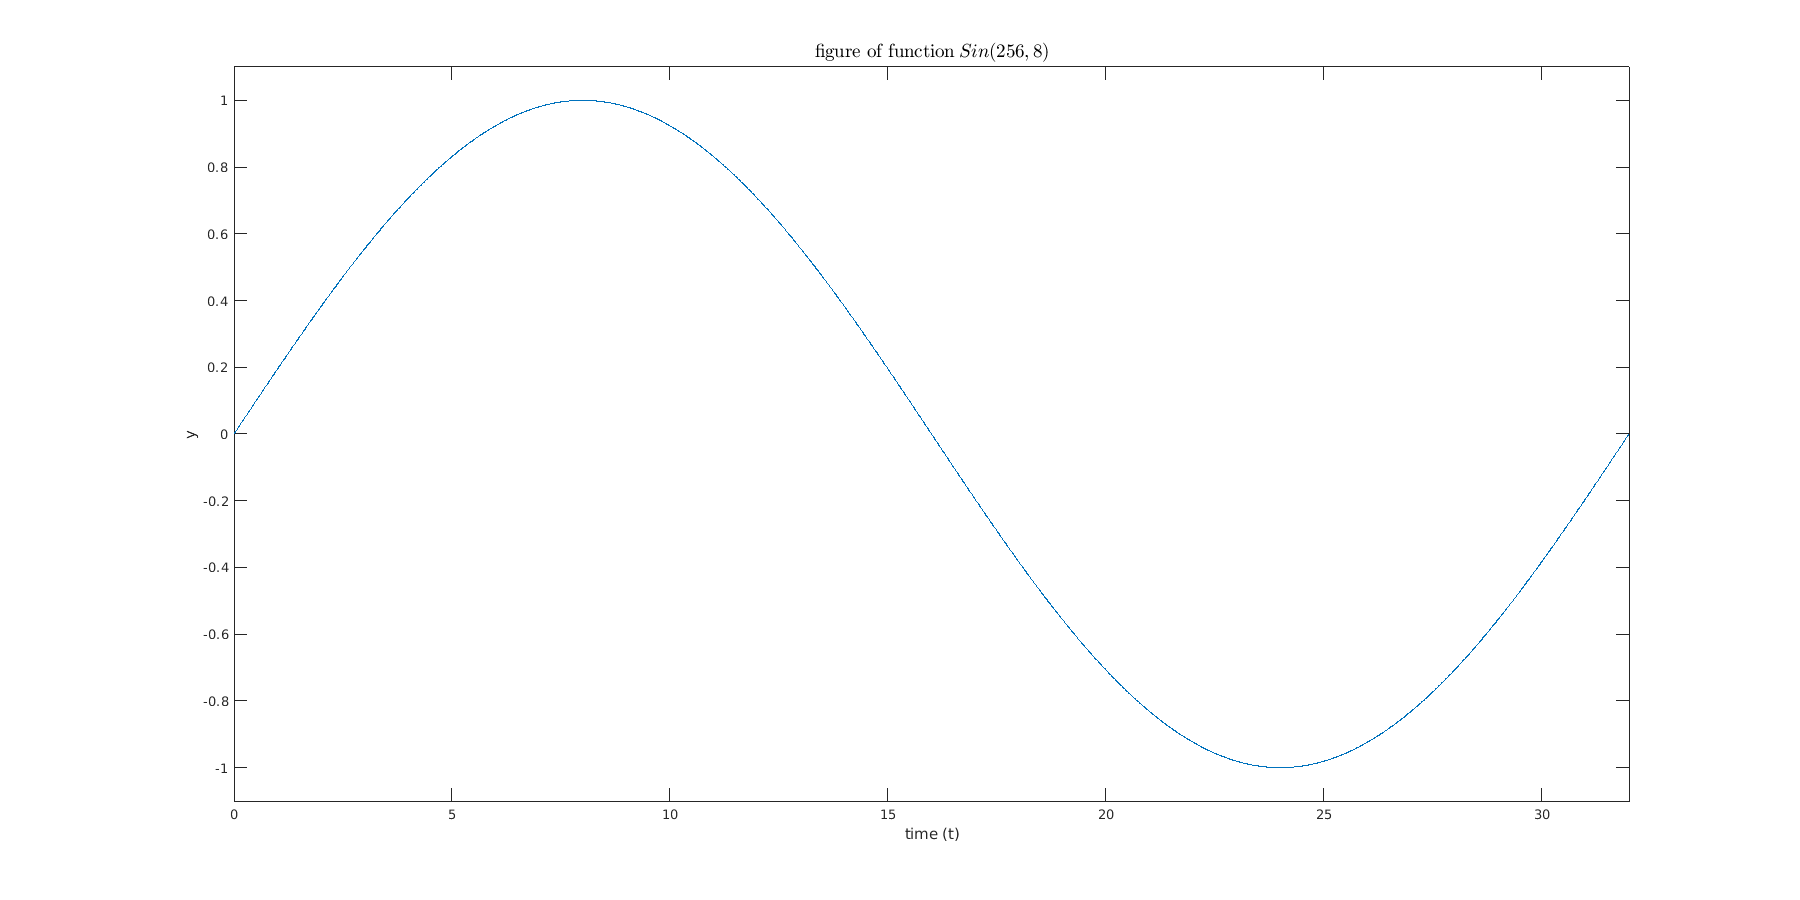

x1 = @(t) sin_func(256,8,t) ;
x2 = @(t) cos_func(256,32,t);
x3 = @(t) 2*x1(t)+x2(t);
x4 = @(t) rect_func(1024,t);

% plot x1
clear title;
time_step_1 = 0.01;
t_1 = 0:time_step_1:256;
fs_1 = 1/time_step_1;
plot_helper(t_1,x1(t_1),"$\: Sin(256,8)$","Sin(256,8)",[0,256/8],[-1.1,1.1]);

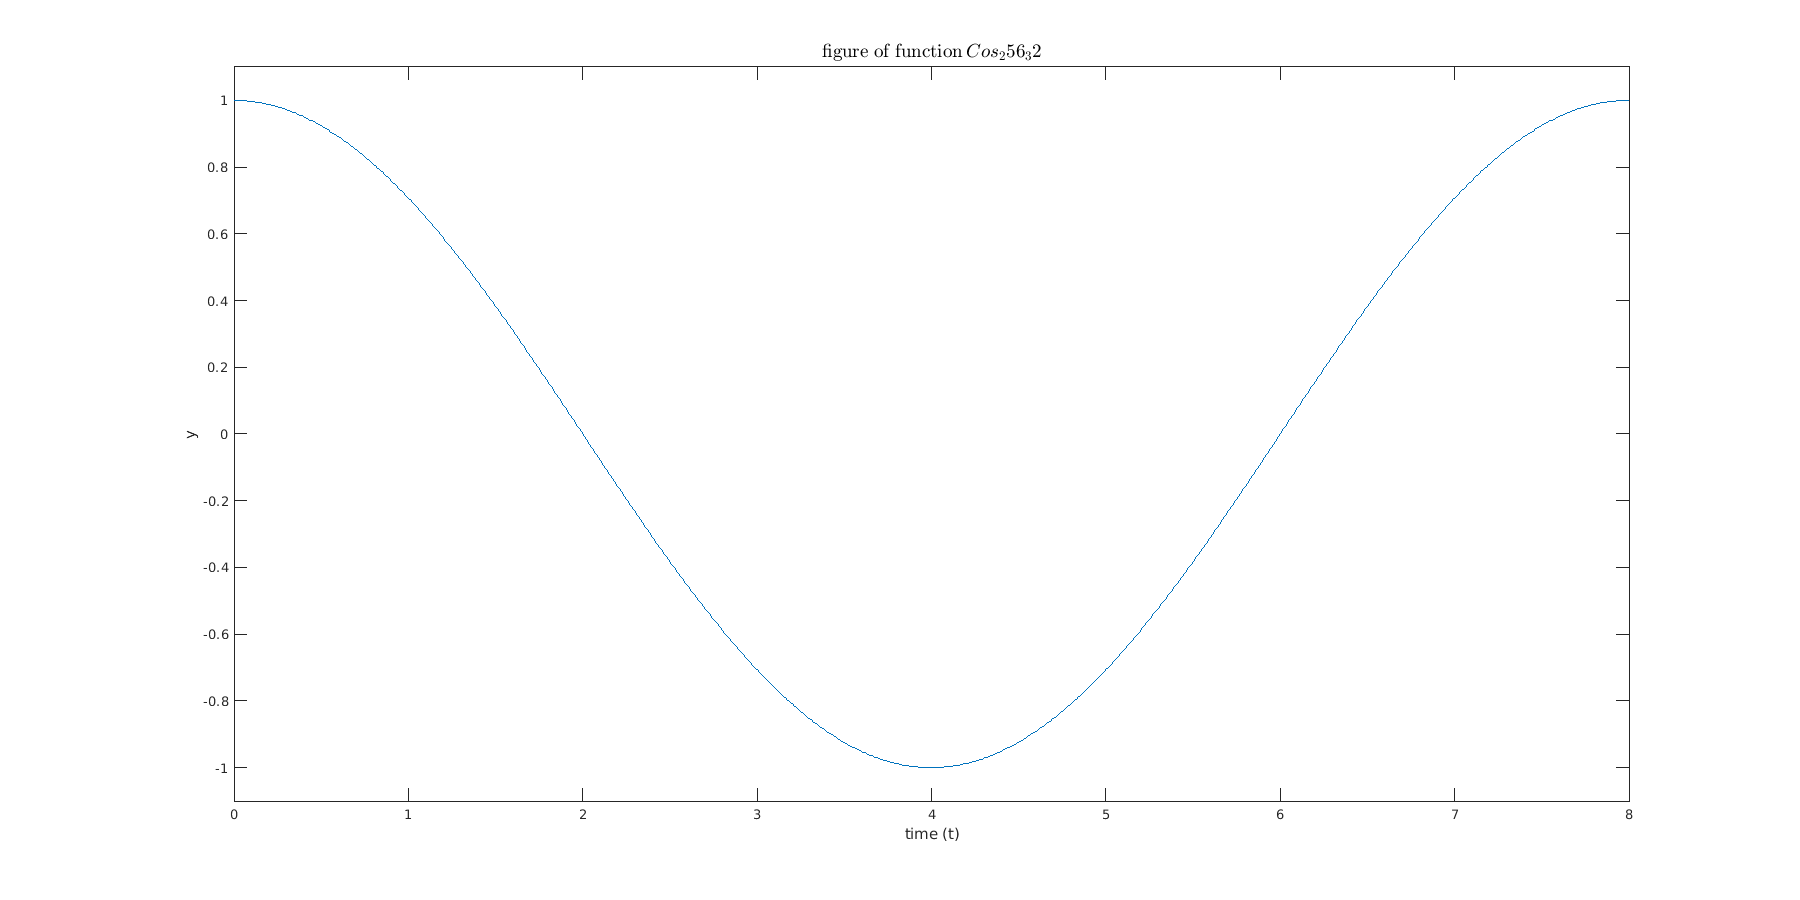


% plot x2
time_step_2 = 0.01;
t_2 = 0:time_step_1:256;
fs_2 = 1/time_step_2;
plot_helper(t_2,x2(t_2),"$\: Cos_256_32$","Cos(256,32)",[0,256/32],[-1.1,1.1]);

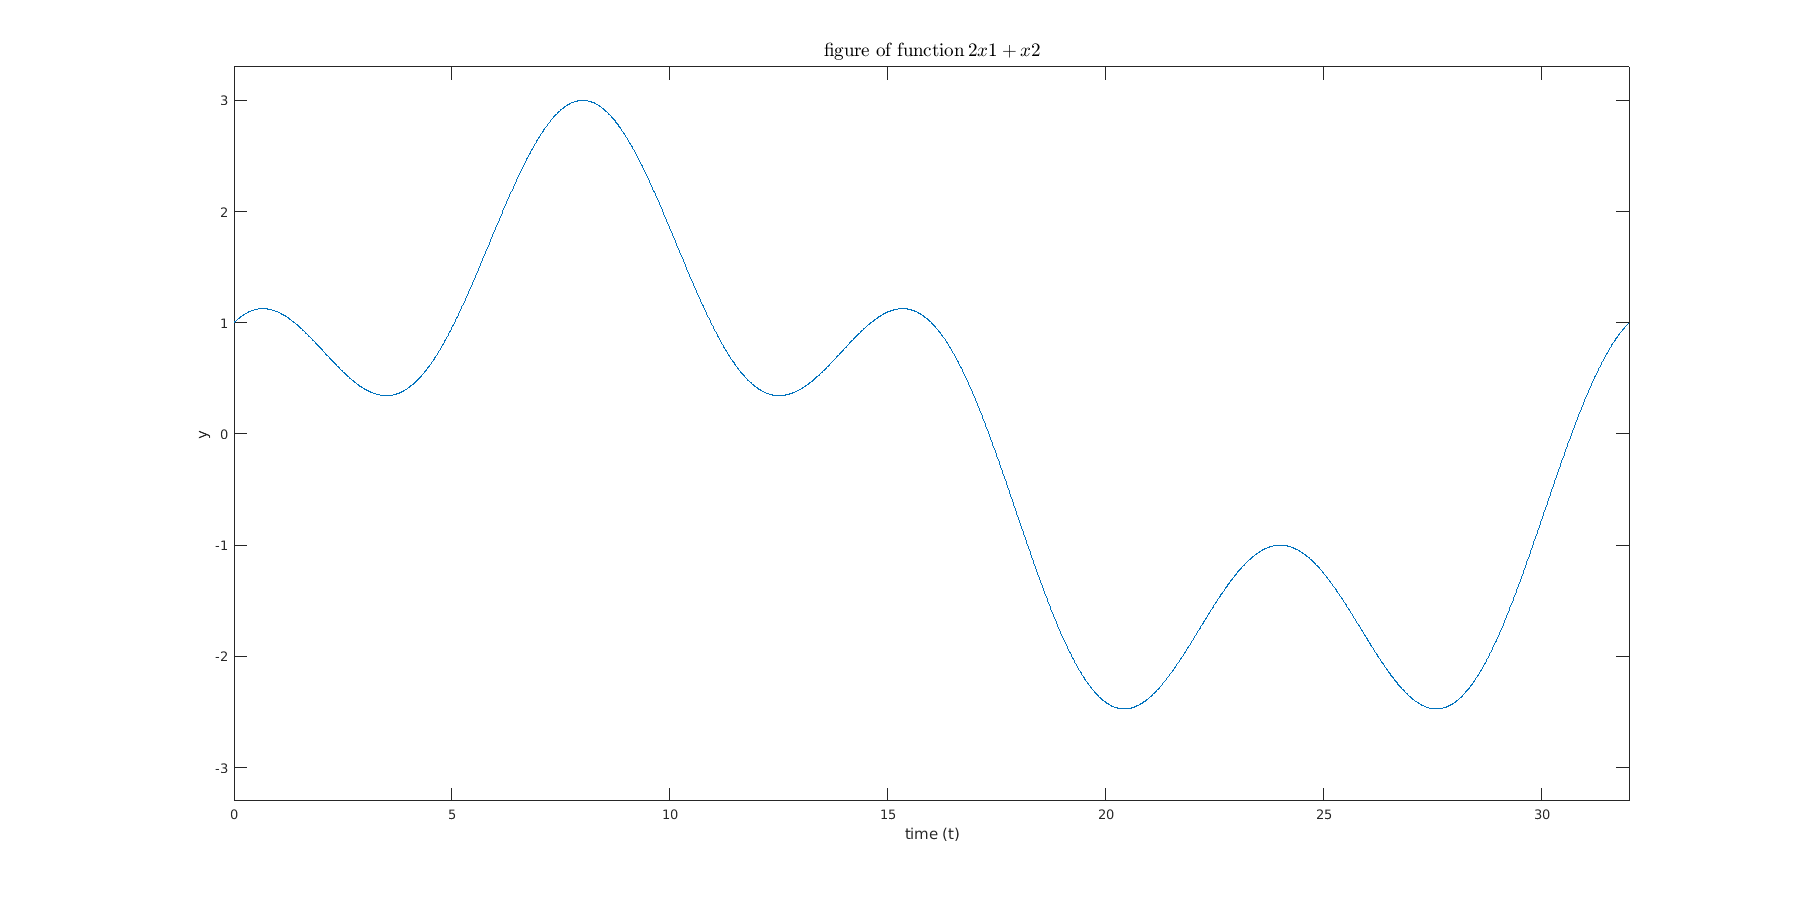


%plot x3
time_step_3 = 0.01;
t_3 = 0:time_step_1:256;
fs_3 = 1/time_step_3;
plot_helper(t_3,x3(t_3),"$\: 2x1+x2$","x3",[0,32],[-3.3,3.3]);

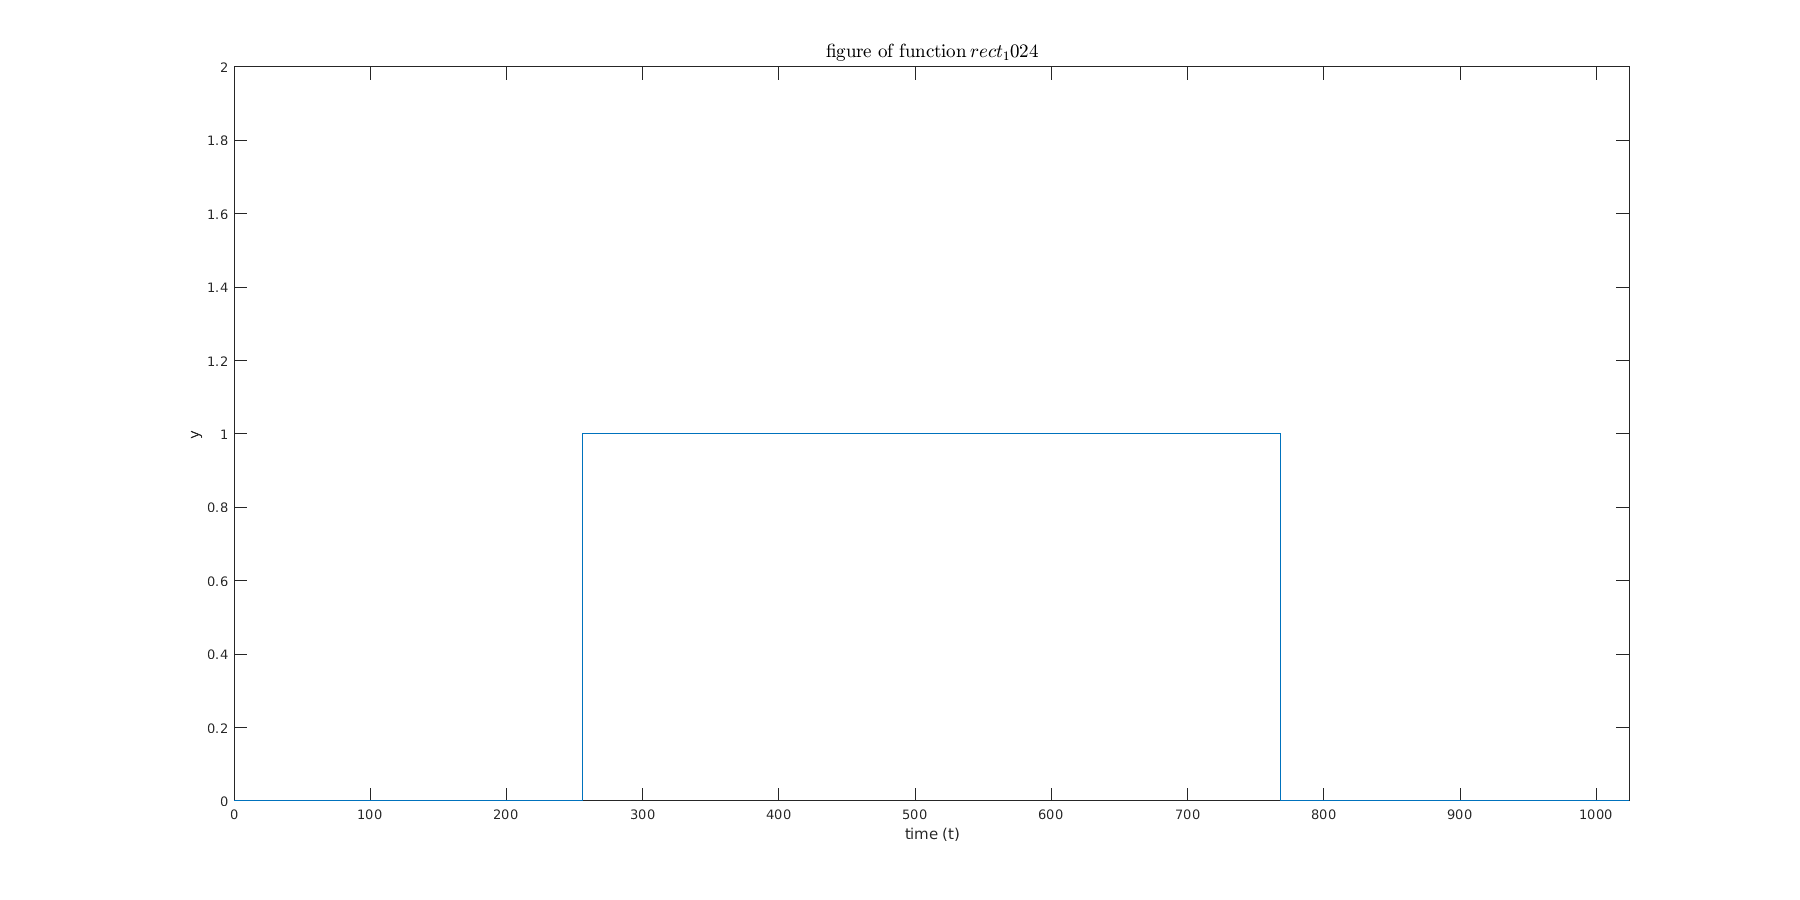


%plot 4
time_step_4 = 0.01;
t_4 = 0:time_step_1:1024;
fs_4 = 1/time_step_4;
plot_helper(t_4,x4(t_4),"$\: rect_1024$","Rect(1024)",[0,1024],[0,2]);

# **part four**

# **function for part four**

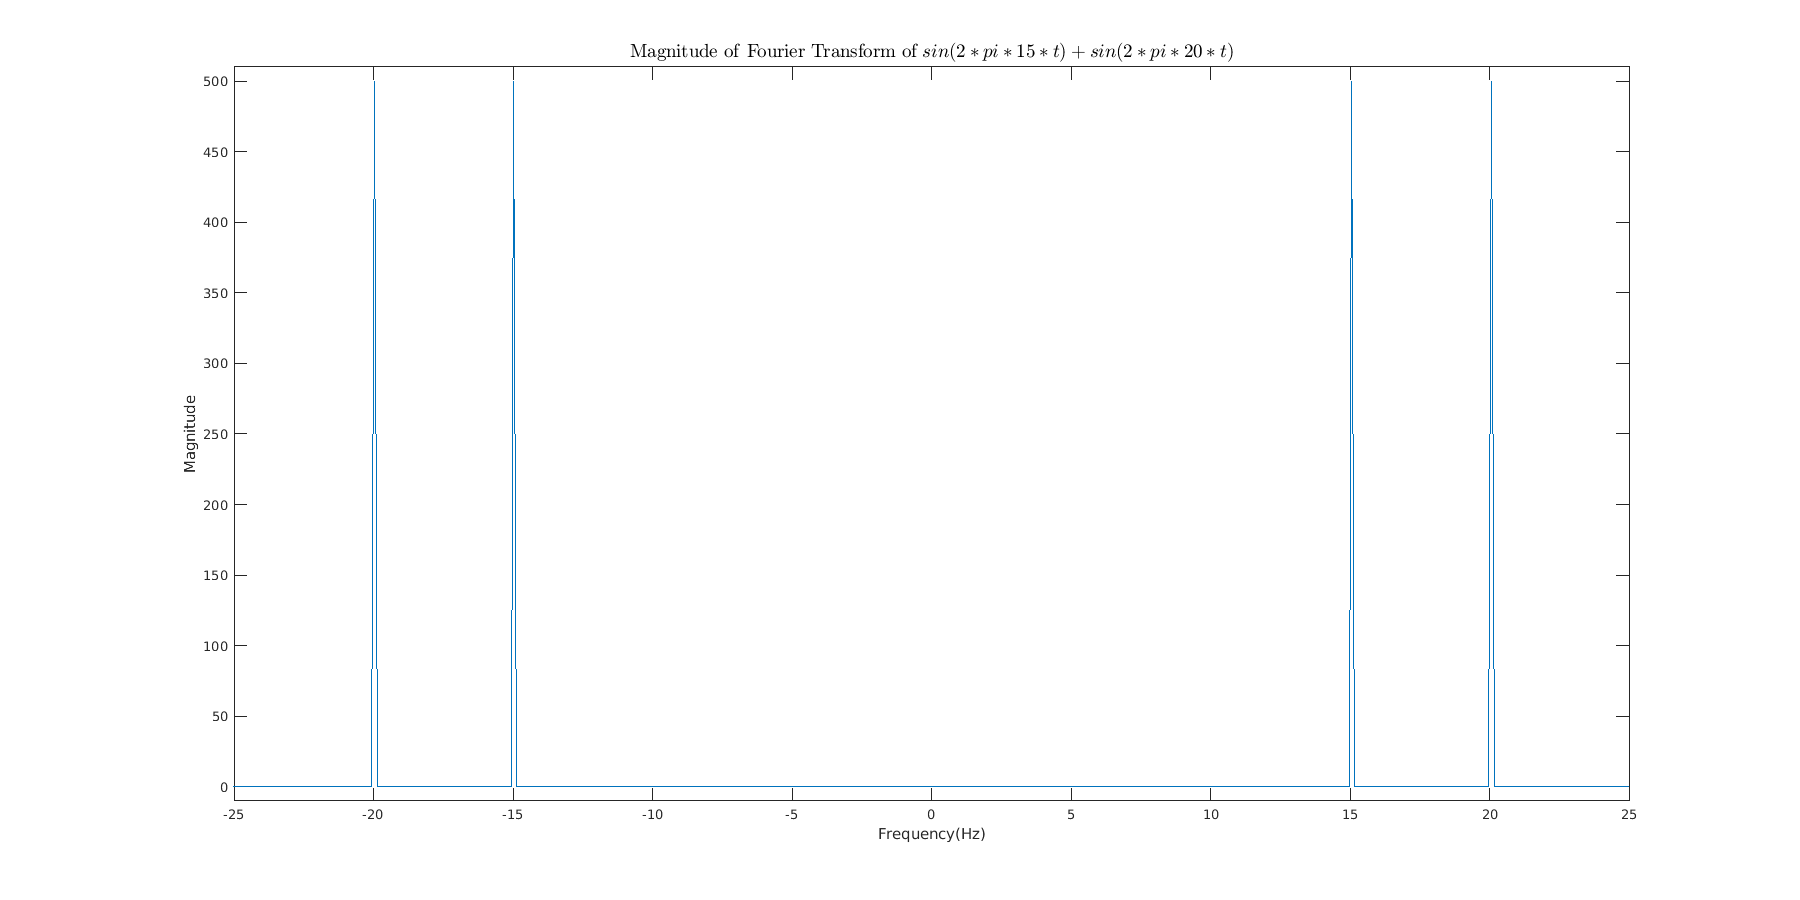

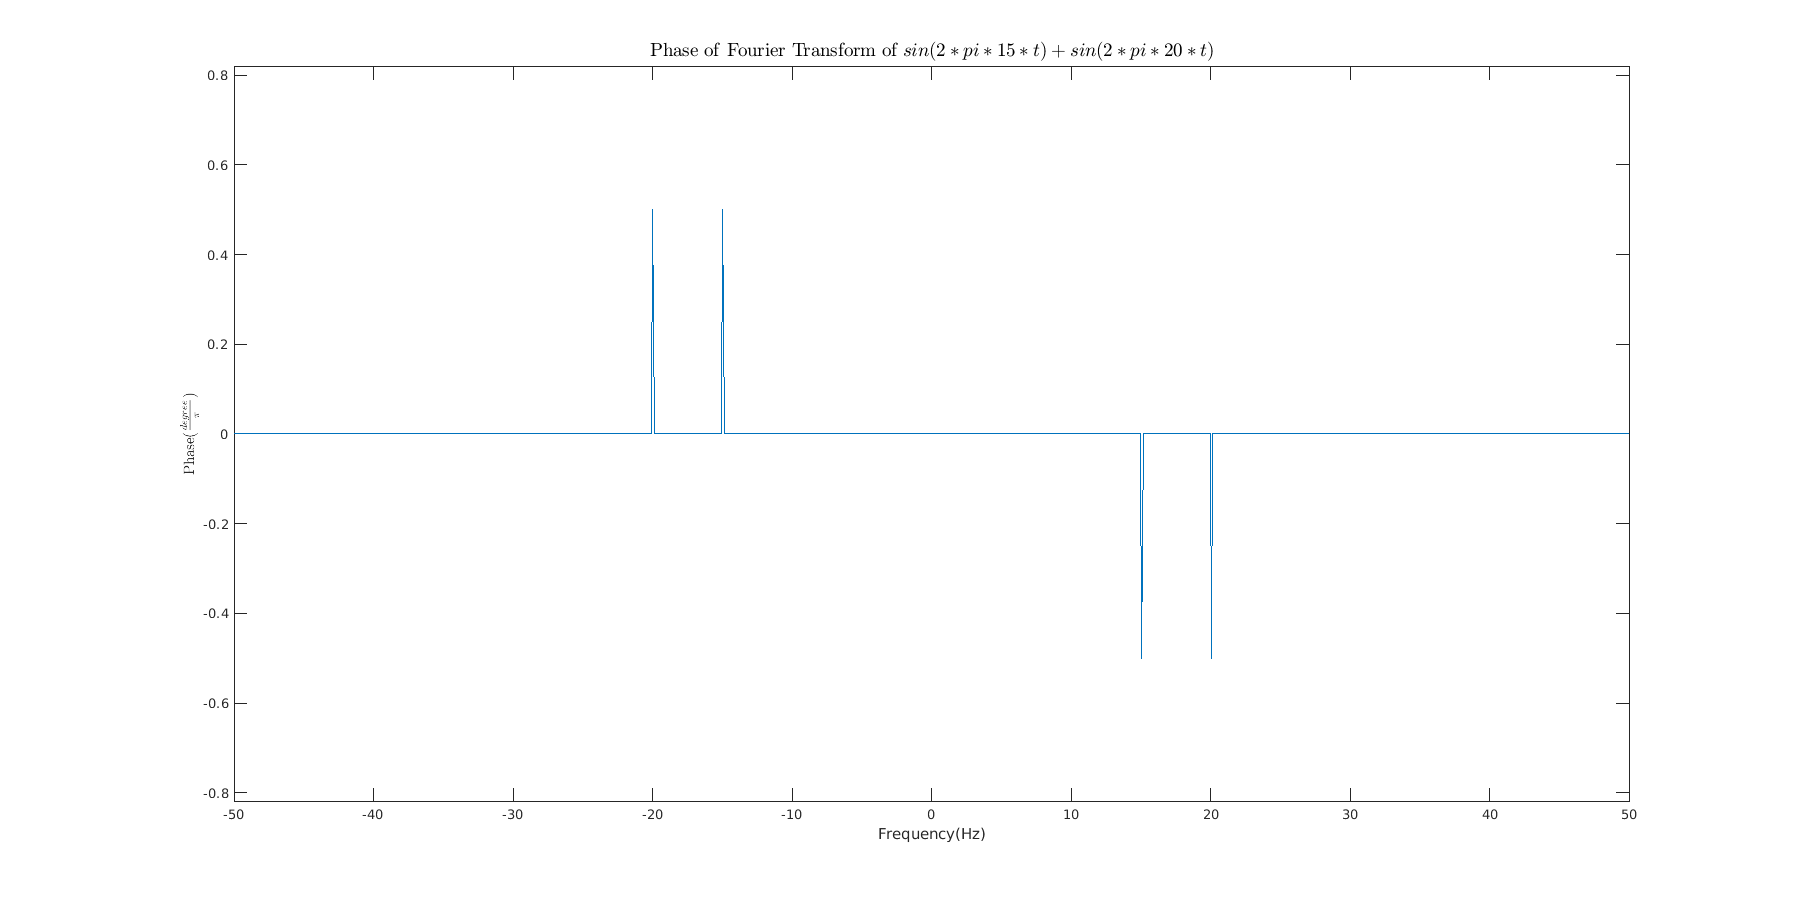

% function is in file ft_top_n_components
% for example for cosine function we have:
Ts = 1/100;
t = 0:Ts:10-Ts;                     
x = sin(2*pi*15*t) + sin(2*pi*20*t);
[w,y,freq] = ft_top_n_components(x,4,1/Ts);
plot_fourier_helper(y,w,10e-10,"$\:sin(2*pi*15*t) + sin(2*pi*20*t)$","sin_example",[-25,25],[0,1.1],[-50,50],[-1.1,1.1]);

display(freq)

freq =    20.0701   15.0651   15.1652   14.9650


# **part five**

**x3**

% x3
[w,y,freq] = ft_top_n_components(x3(t_3),4,fs_3);
display(freq);

freq =     0.0312    0.1250    0.1211    0.1289


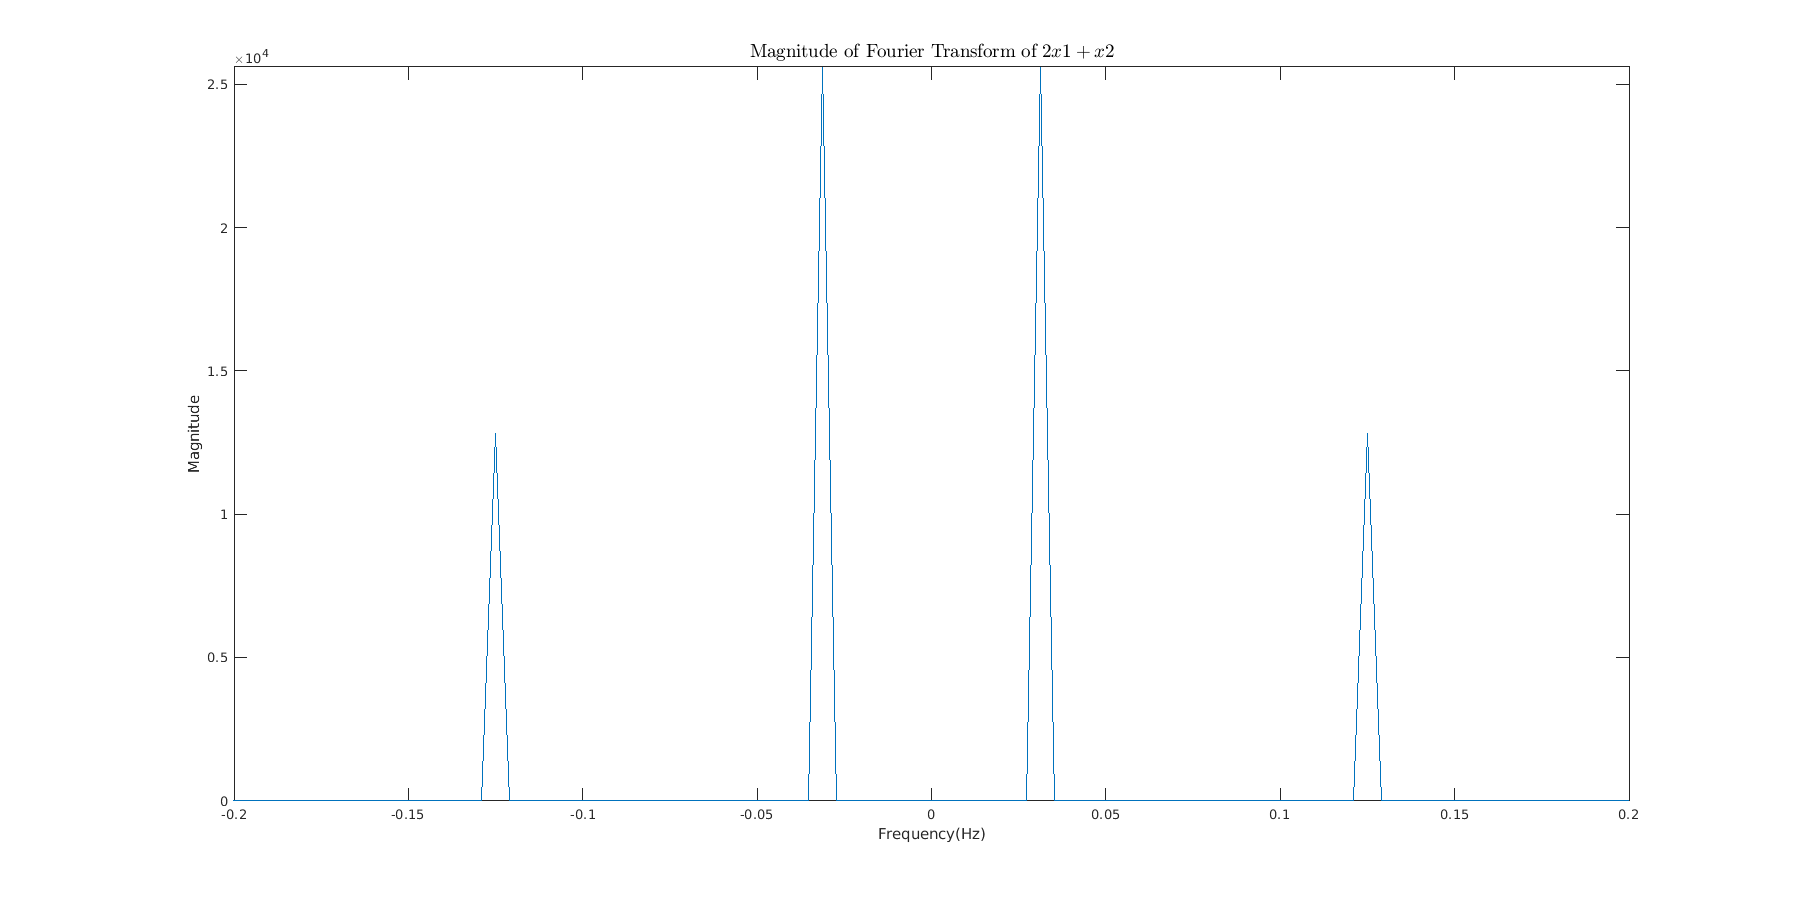

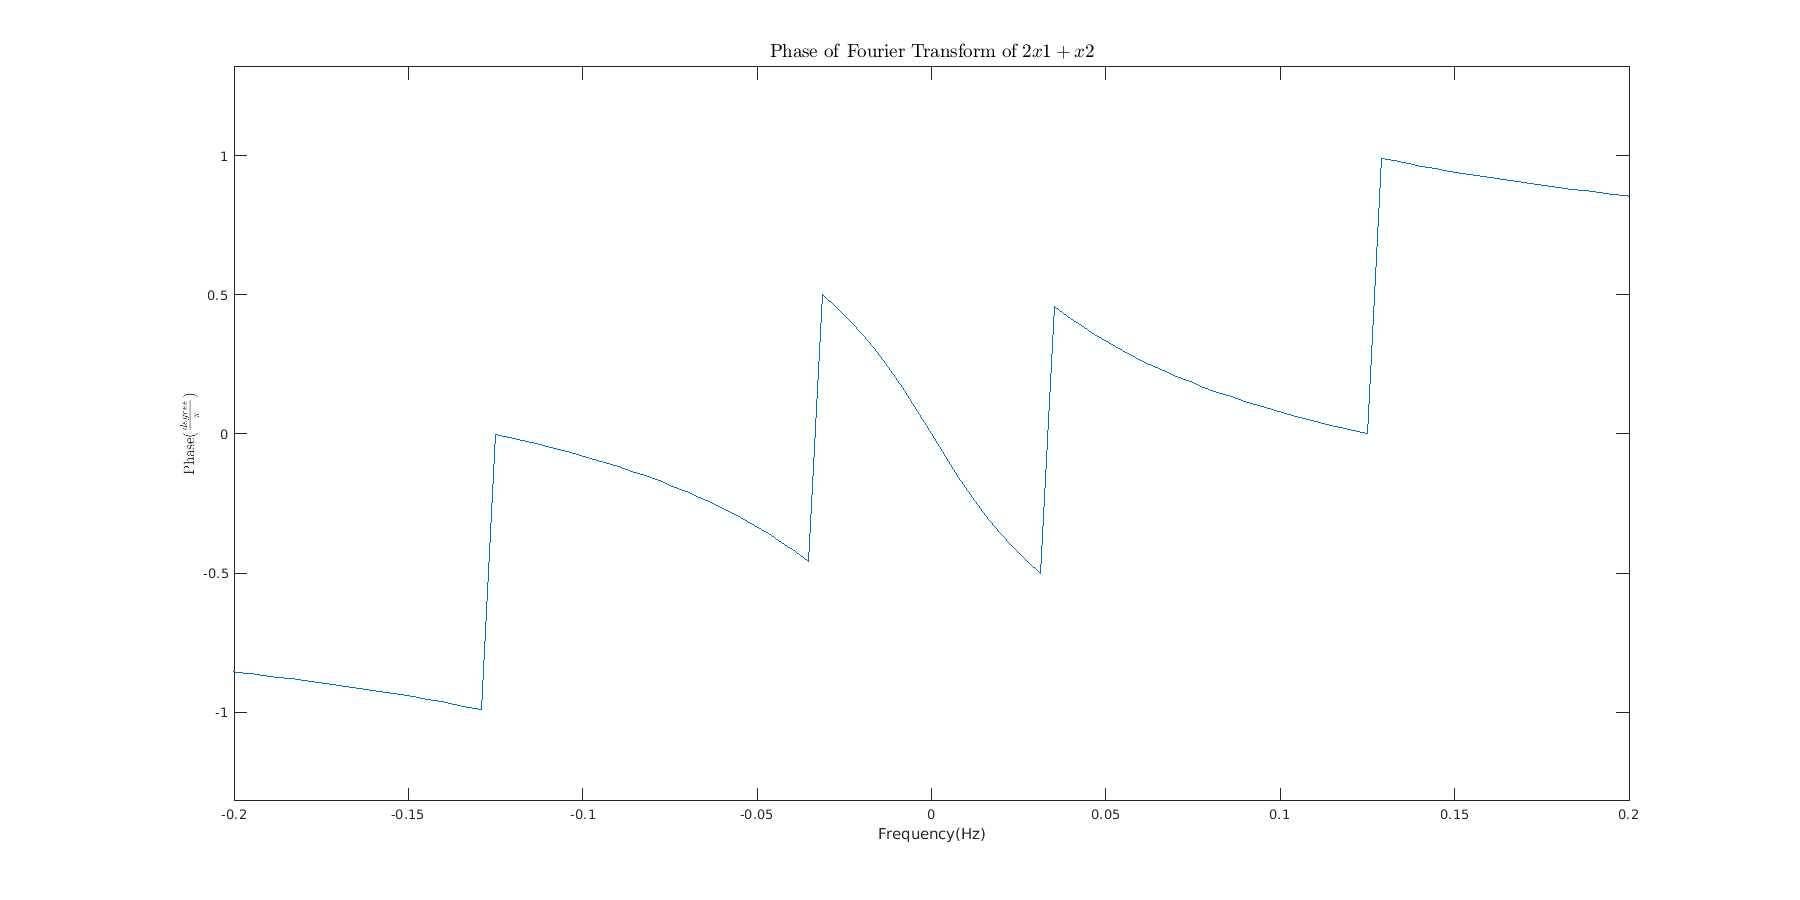


plot_fourier_helper(y,w,10e-10,"$\:2x1+x2$","x3",[-0.2,0.2],[0,1.1],[-0.2,0.2],[-1.1,1.1]);


[w,y,freq] = ft_top_n_components(x4(t_4),4,fs_4);
display(freq);

freq =          0    0.0010    0.0029    0.0049


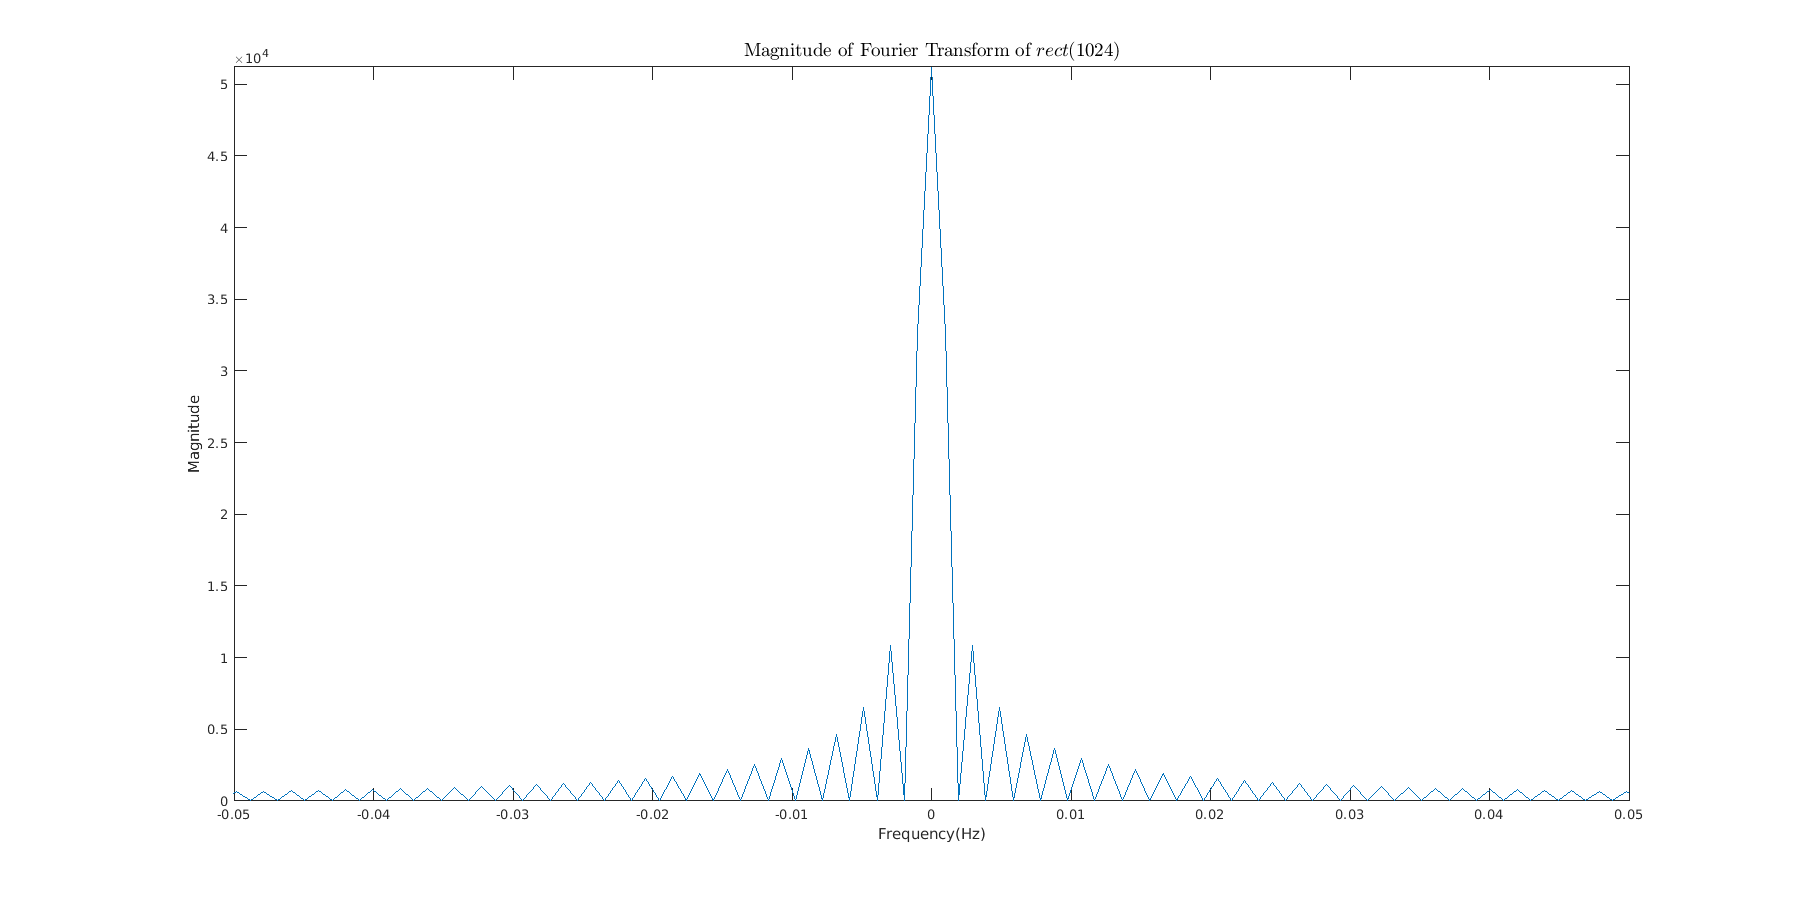

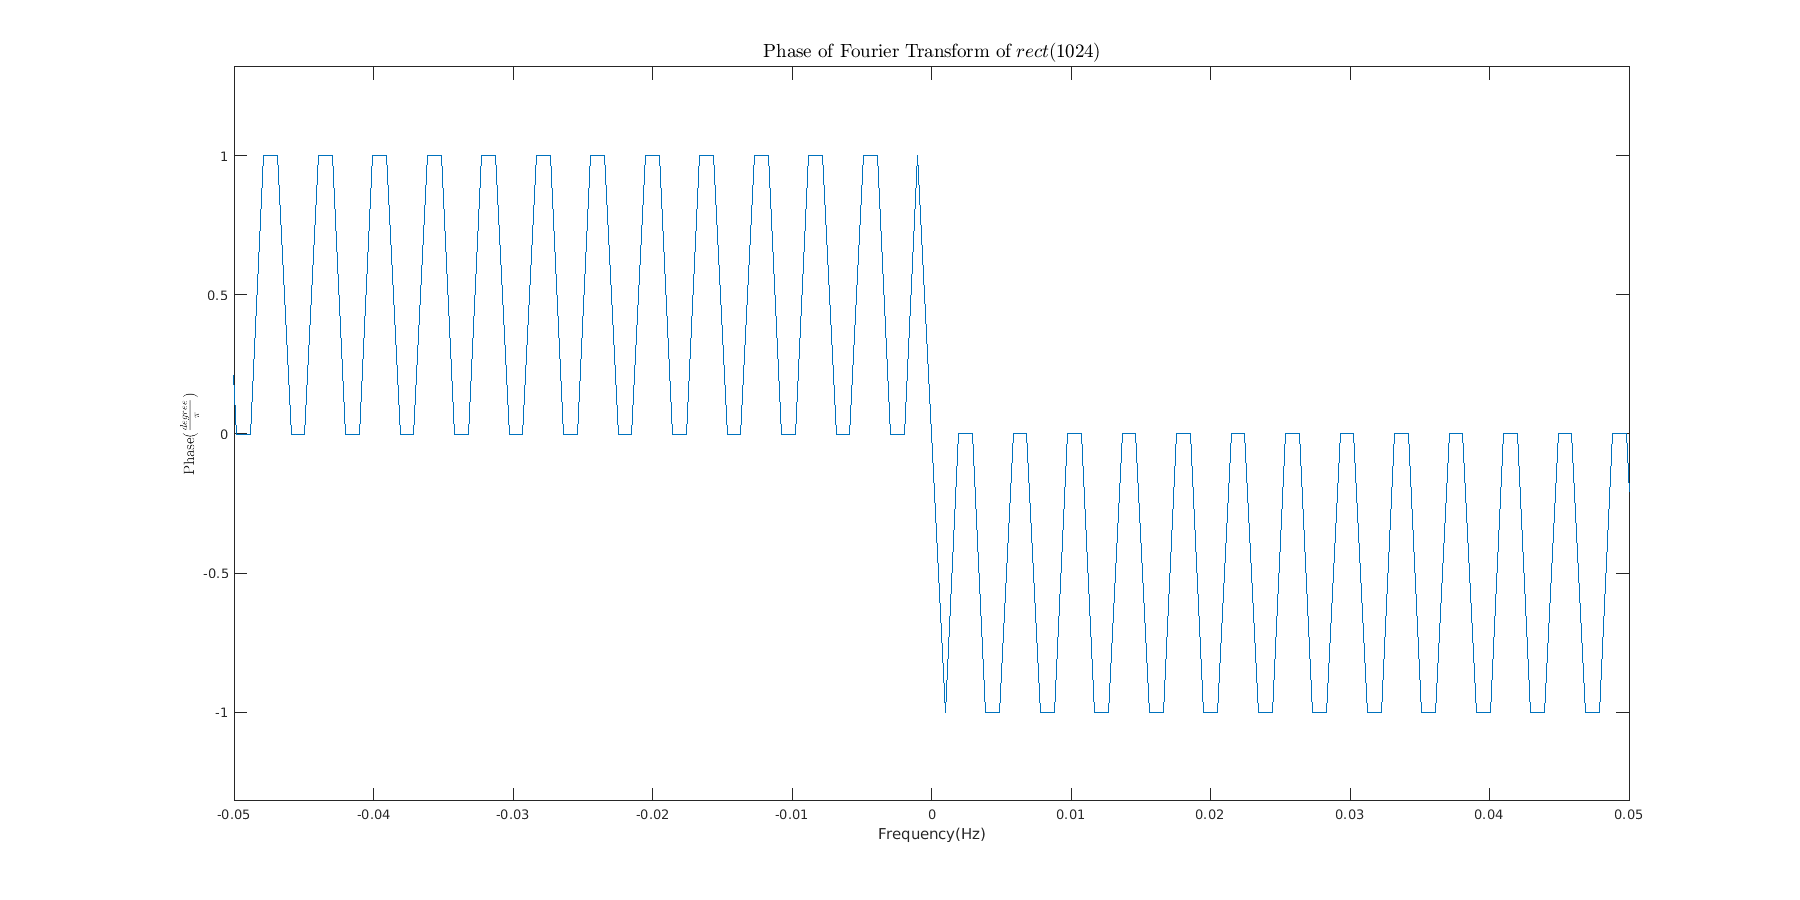

plot_fourier_helper(y,w,10e-6,"$\:rect(1024)$","rect",[-0.05,0.05],[0,1],[-0.05,0.05],[-1.1,1.1]);

# **part six**

%x5
x5 = @(t) cos_func(128,16,t);
time_step_5 = 0.01;
t_5 = -0:time_step_5:128;
fs_5 = 1/time_step_5;
[w,y,freq] = ft_top_n_components(x5(t_5),4,fs_5);
display(freq);

freq =     0.1250    0.1172    0.1328    0.1094


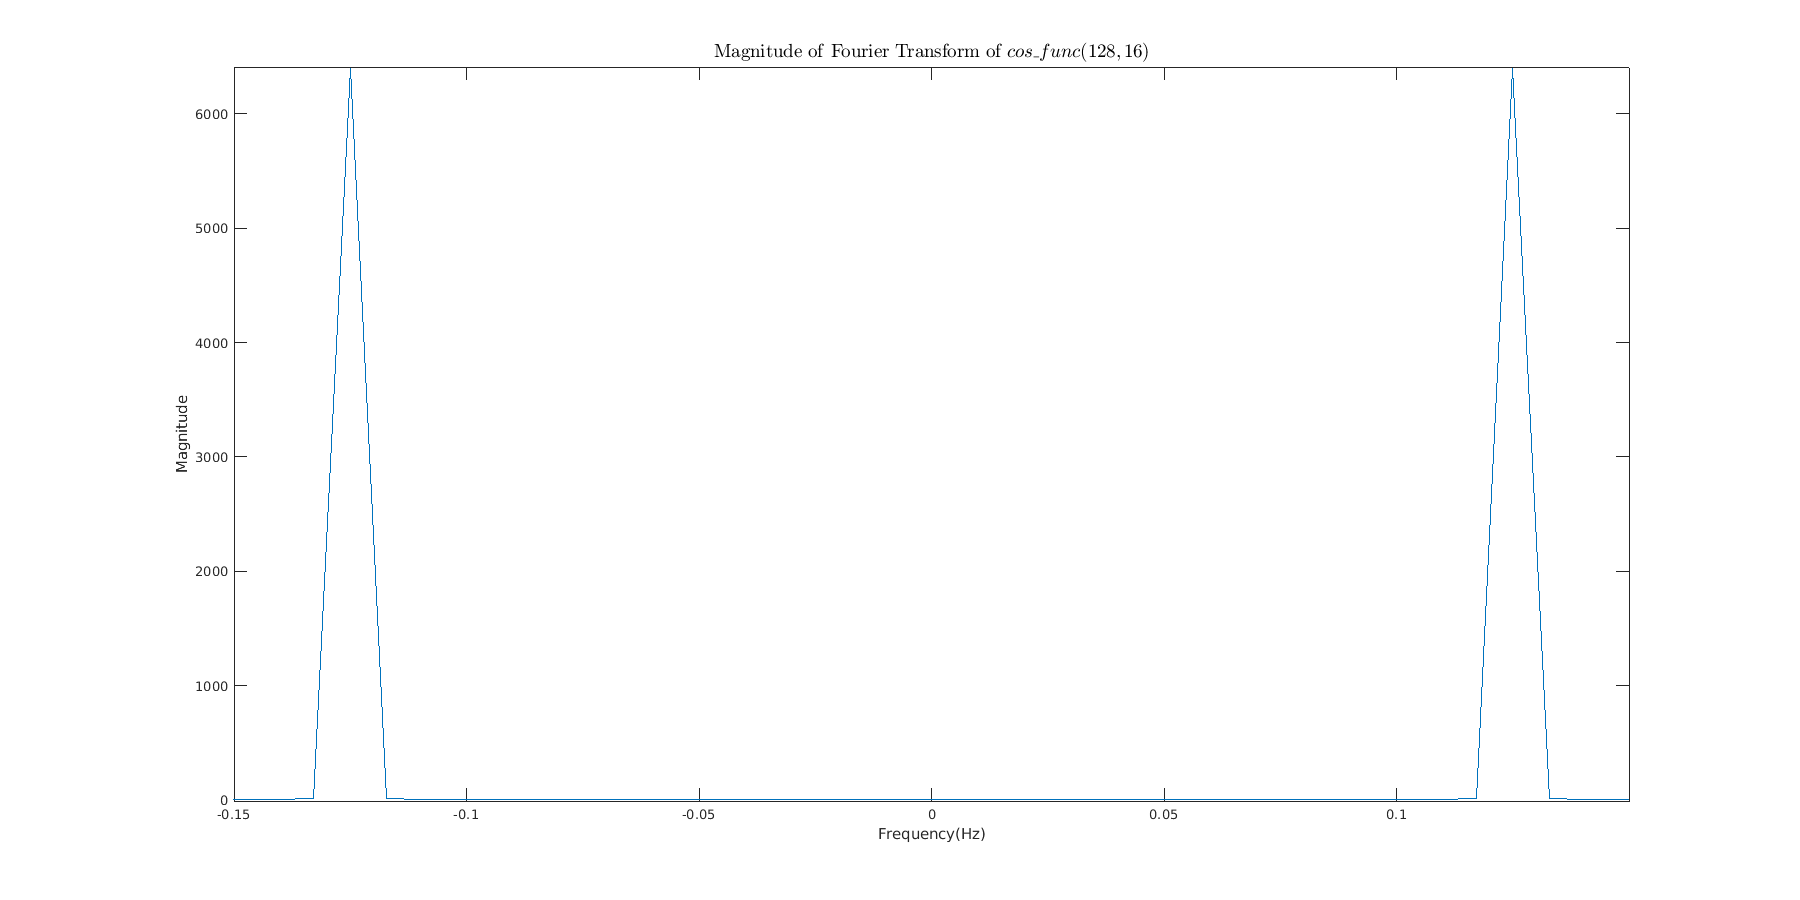

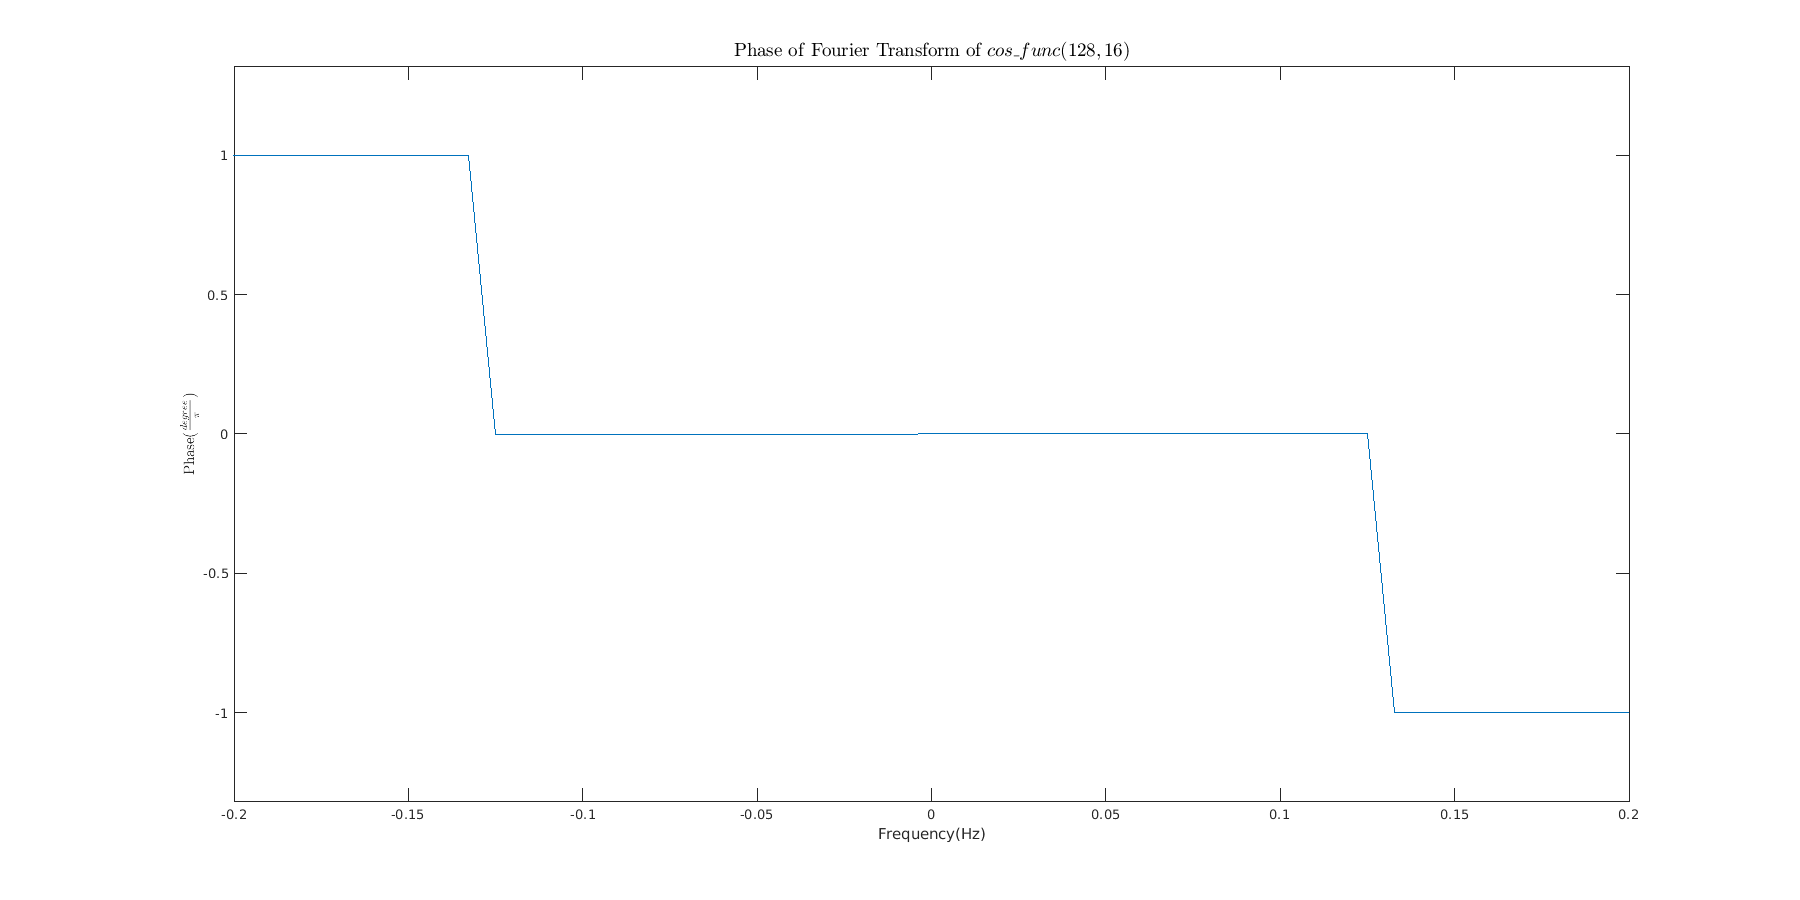

plot_fourier_helper(y,w,10e-6,"$\:cos\_func(128,16)$","cosfunc(128,16)",[-0.15,0.15],[0,1.1],[-0.2,0.2],[-1.5,1.5]);


%x6
x6 = @(t) cos_func(512,64,t);
time_step_6 = 0.01;
t_6 = -0:time_step_6:512;
fs_6 = 1/time_step_6;
[w,y,freq] = ft_top_n_components(x6(t_6),4,fs_6);
display(freq);

freq =     0.1250    0.1230    0.1270    0.1211


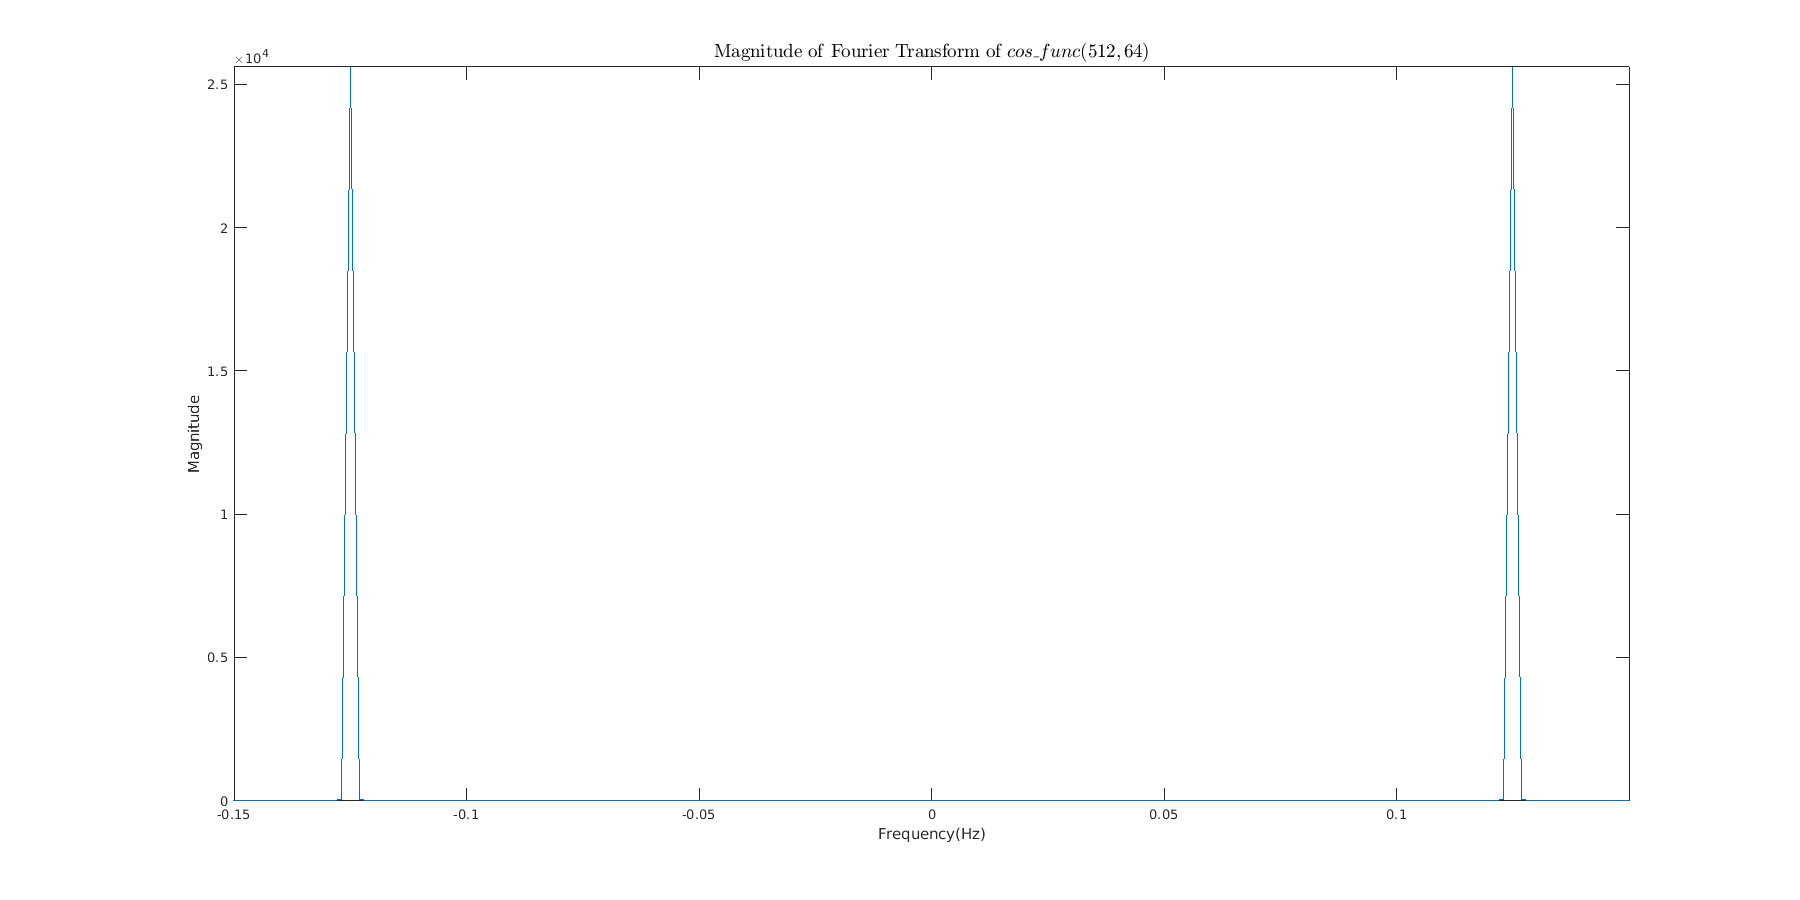

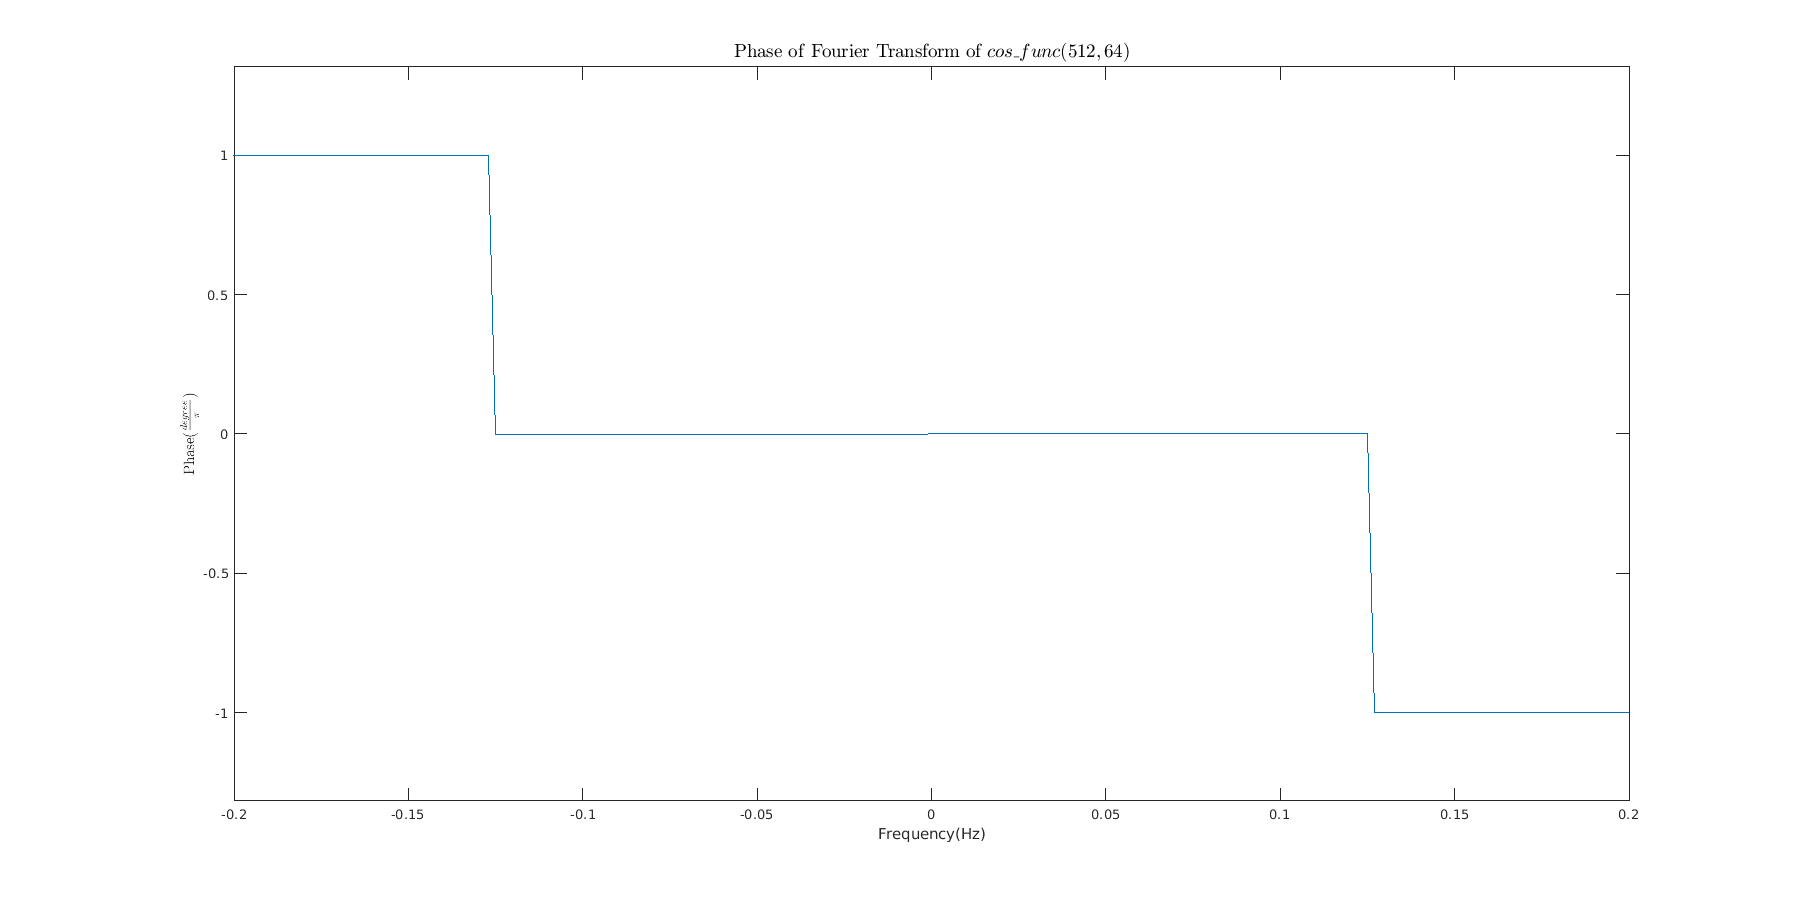

plot_fourier_helper(y,w,10e-6,"$\:cos\_func(512,64)$","cosfunc(512,64)",[-0.15,0.15],[0,1.1],[-0.2,0.2],[-1.5,1.5]);

%x7
x7 = @(t) cos_func(2048,256,t);
time_step_7 = 0.01;
t_7 = -0:time_step_7:2048;
fs_7 = 1/time_step_7;
[w,y,freq] = ft_top_n_components(x7(t_7),4,fs_7);
display(freq);

freq =     0.1250    0.1245    0.1255    0.1240


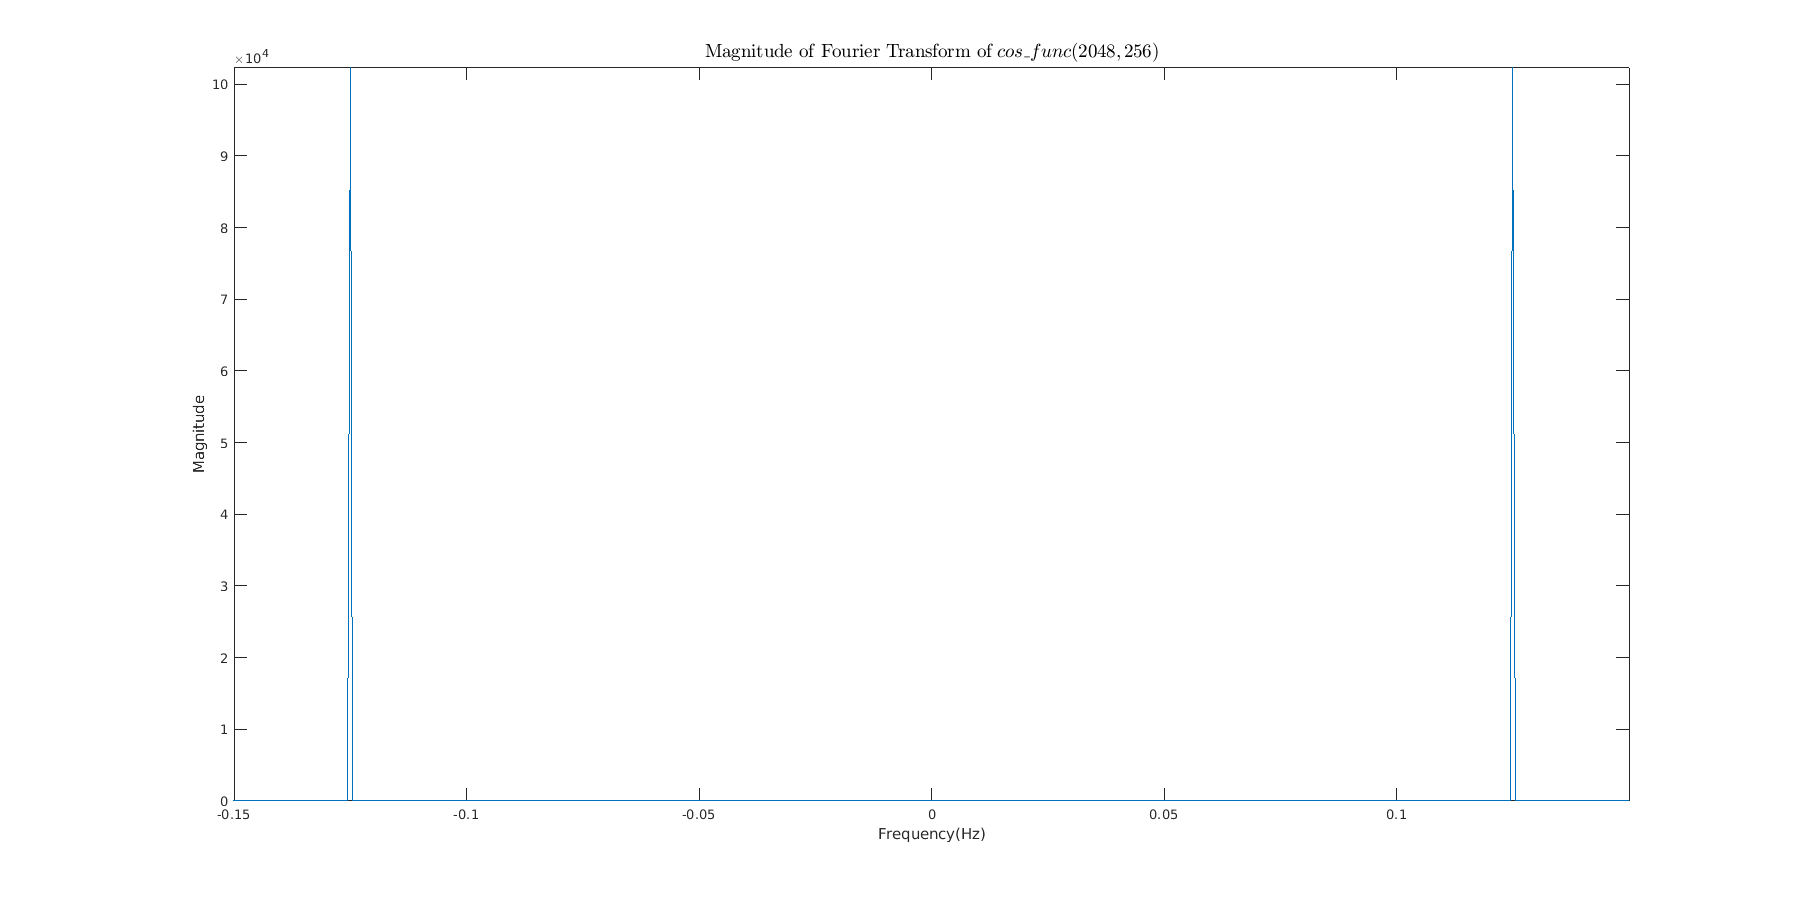

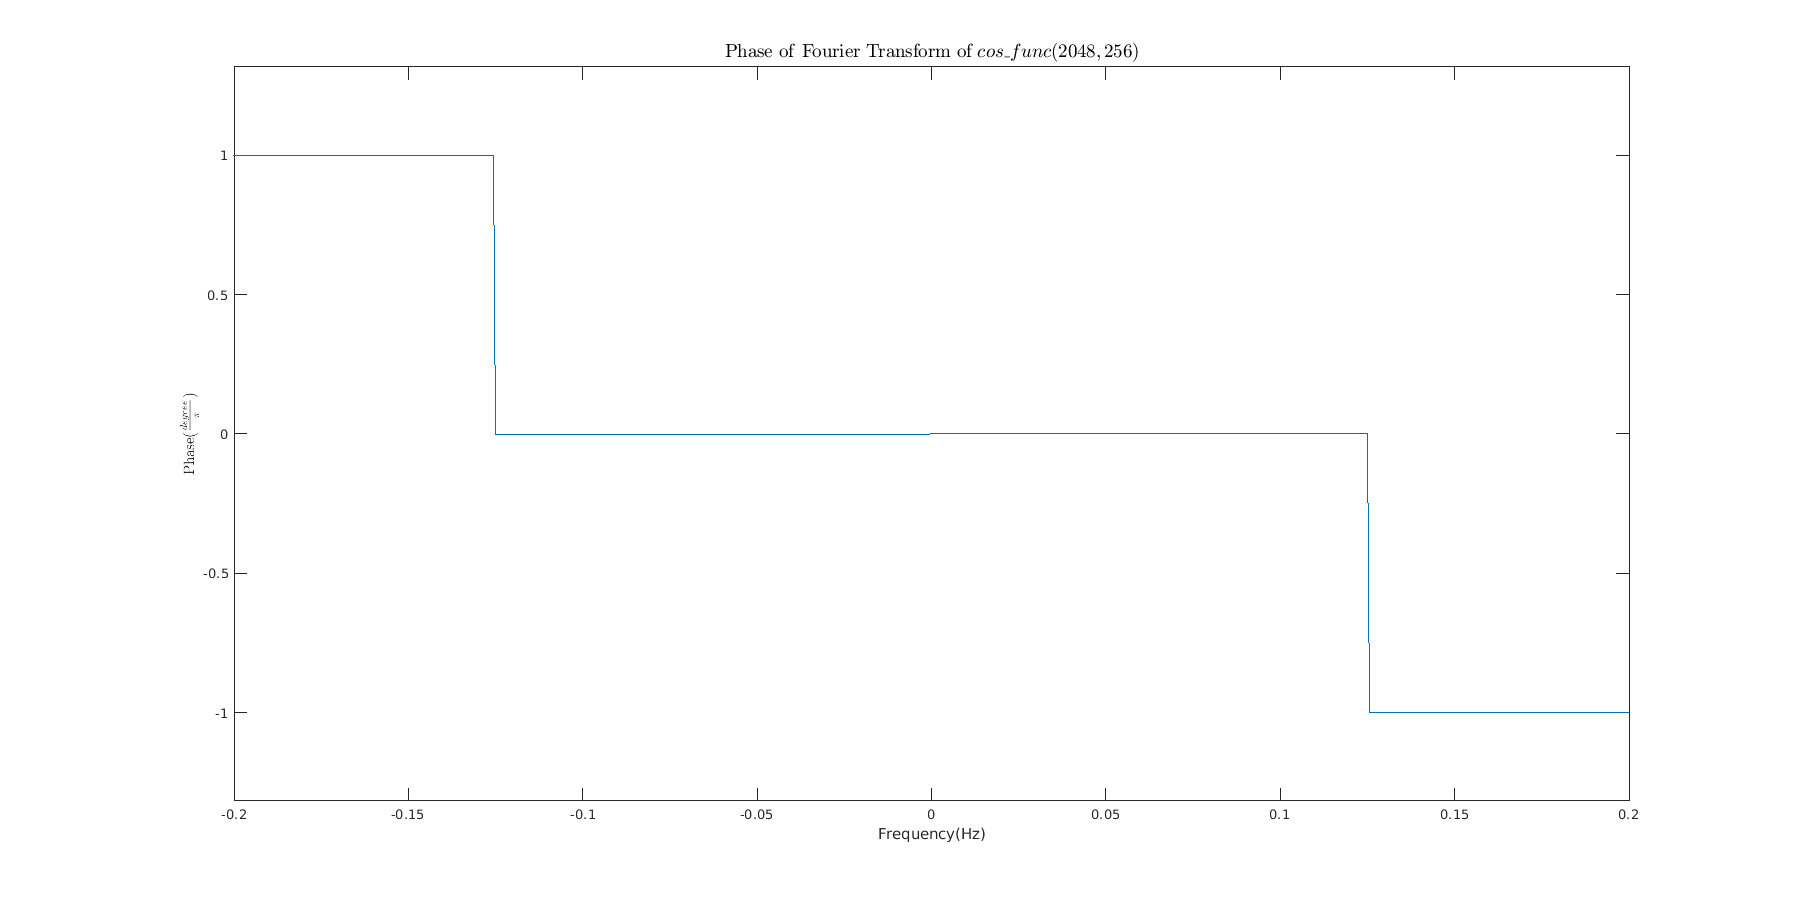

plot_fourier_helper(y,w,10e-6,"$\:cos\_func(2048,256)$","cosfunc(2048,256)",[-0.15,0.15],[0,1.1],[-0.2,0.2],[-1.5,1.5]);

# **part seven**

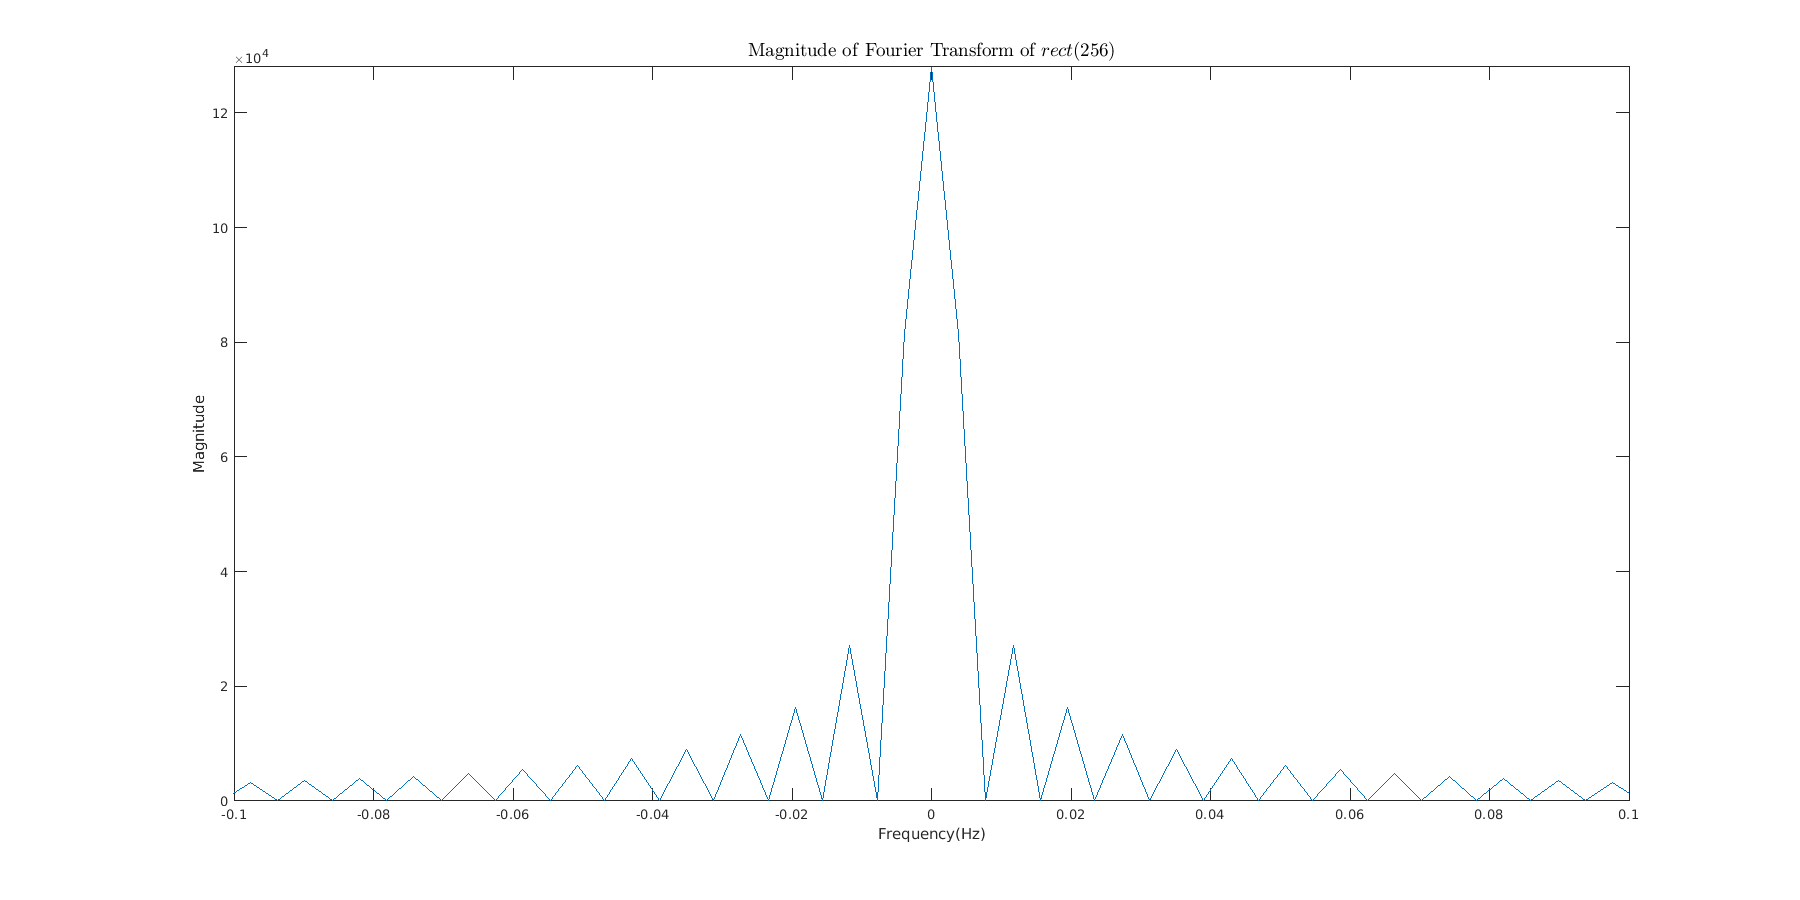

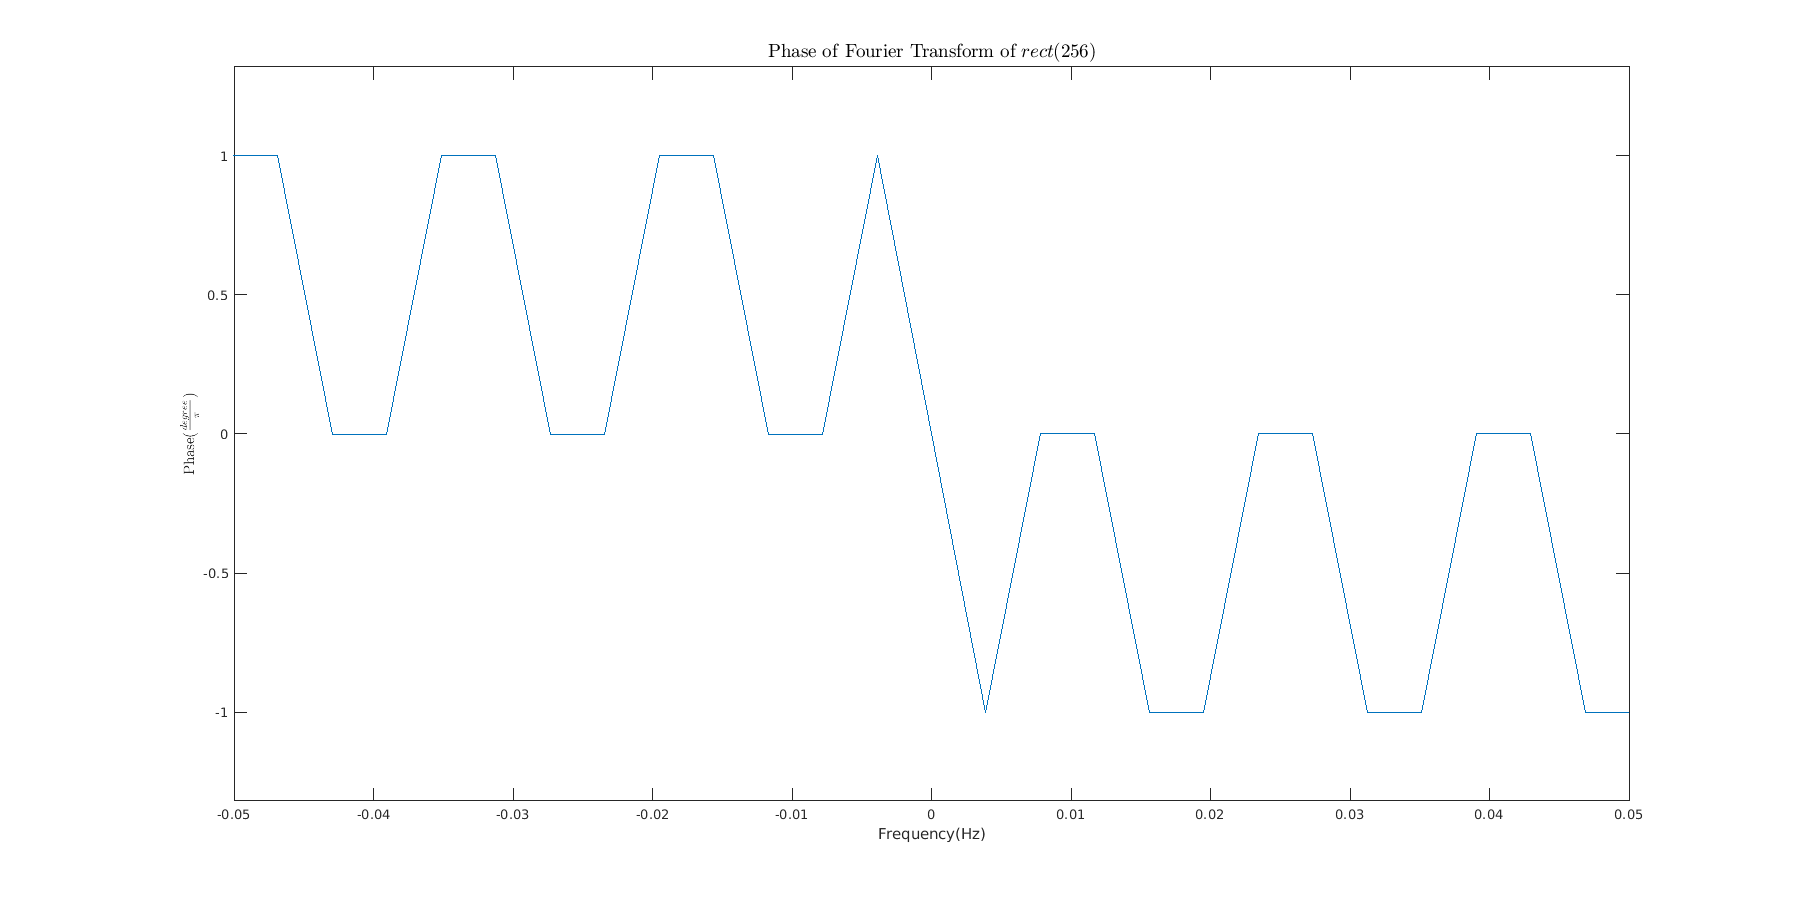

%x8
x8 = @(t) rect_func(256,t);
time_step_8 = 0.001;
t_8 = -0:time_step_8:256;
fs_8 = 1/time_step_8;
[w,y,freq] = ft_top_n_components(x8(t_8),4,fs_8);
plot_fourier_helper(y,w,10e-6,"$\:rect(256)$","rect256",[-0.1,0.1],[0,1],[-0.05,0.05],[-1.1,1.1]);

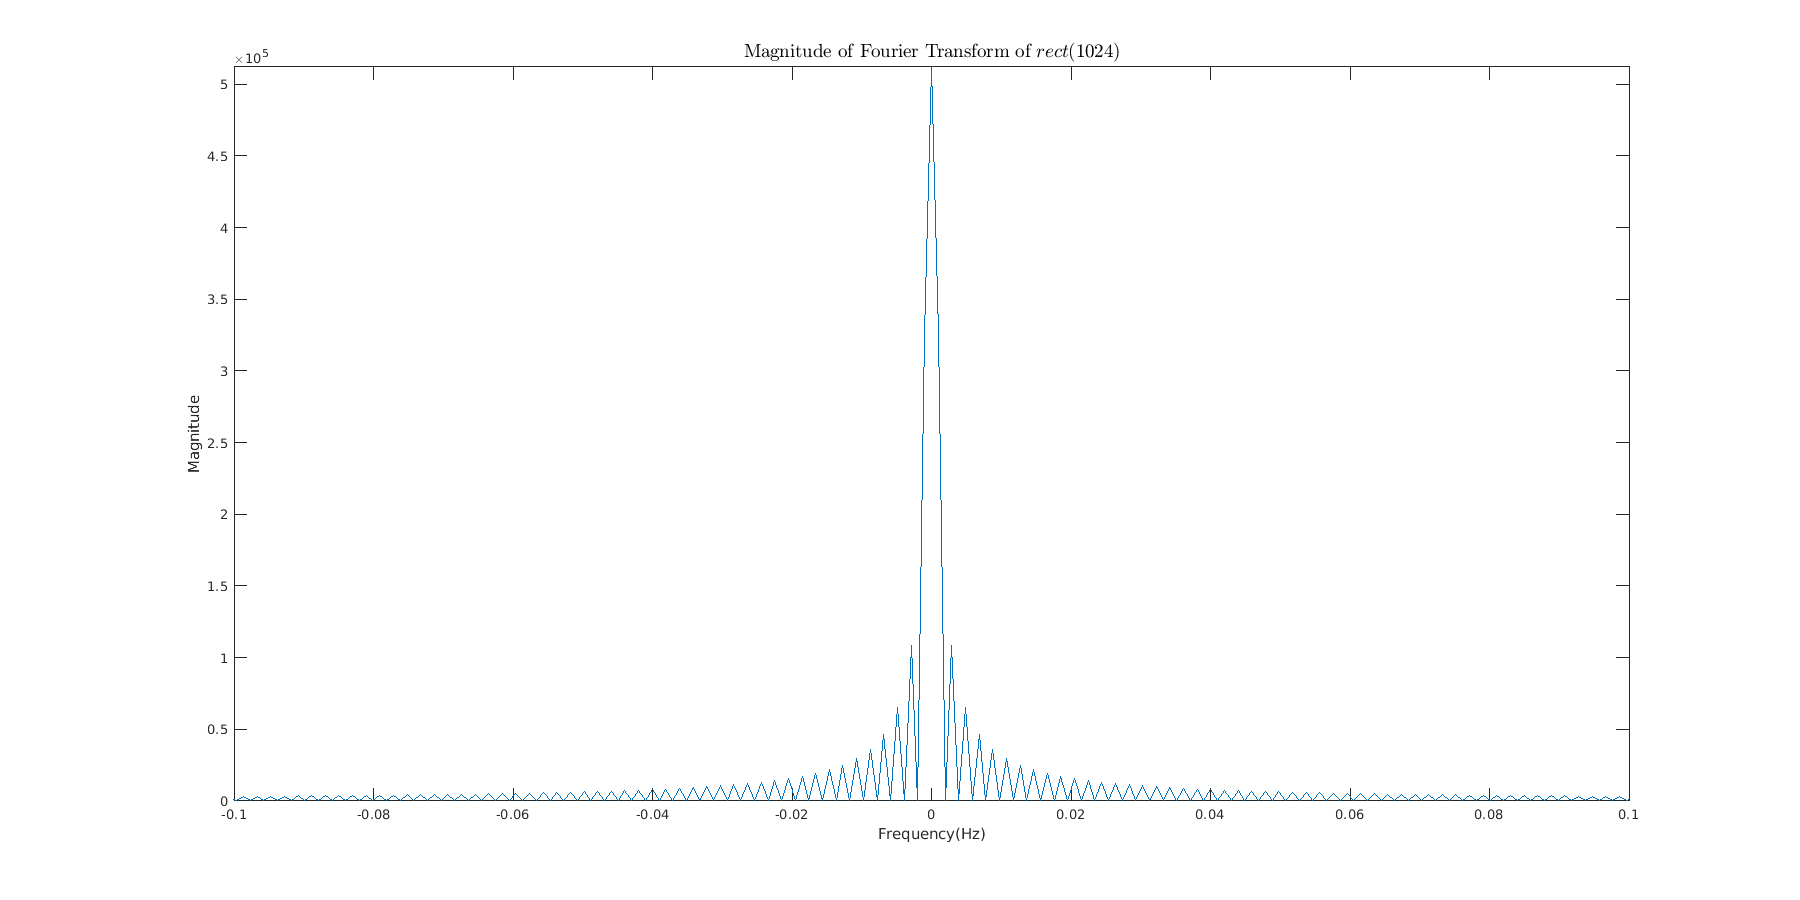

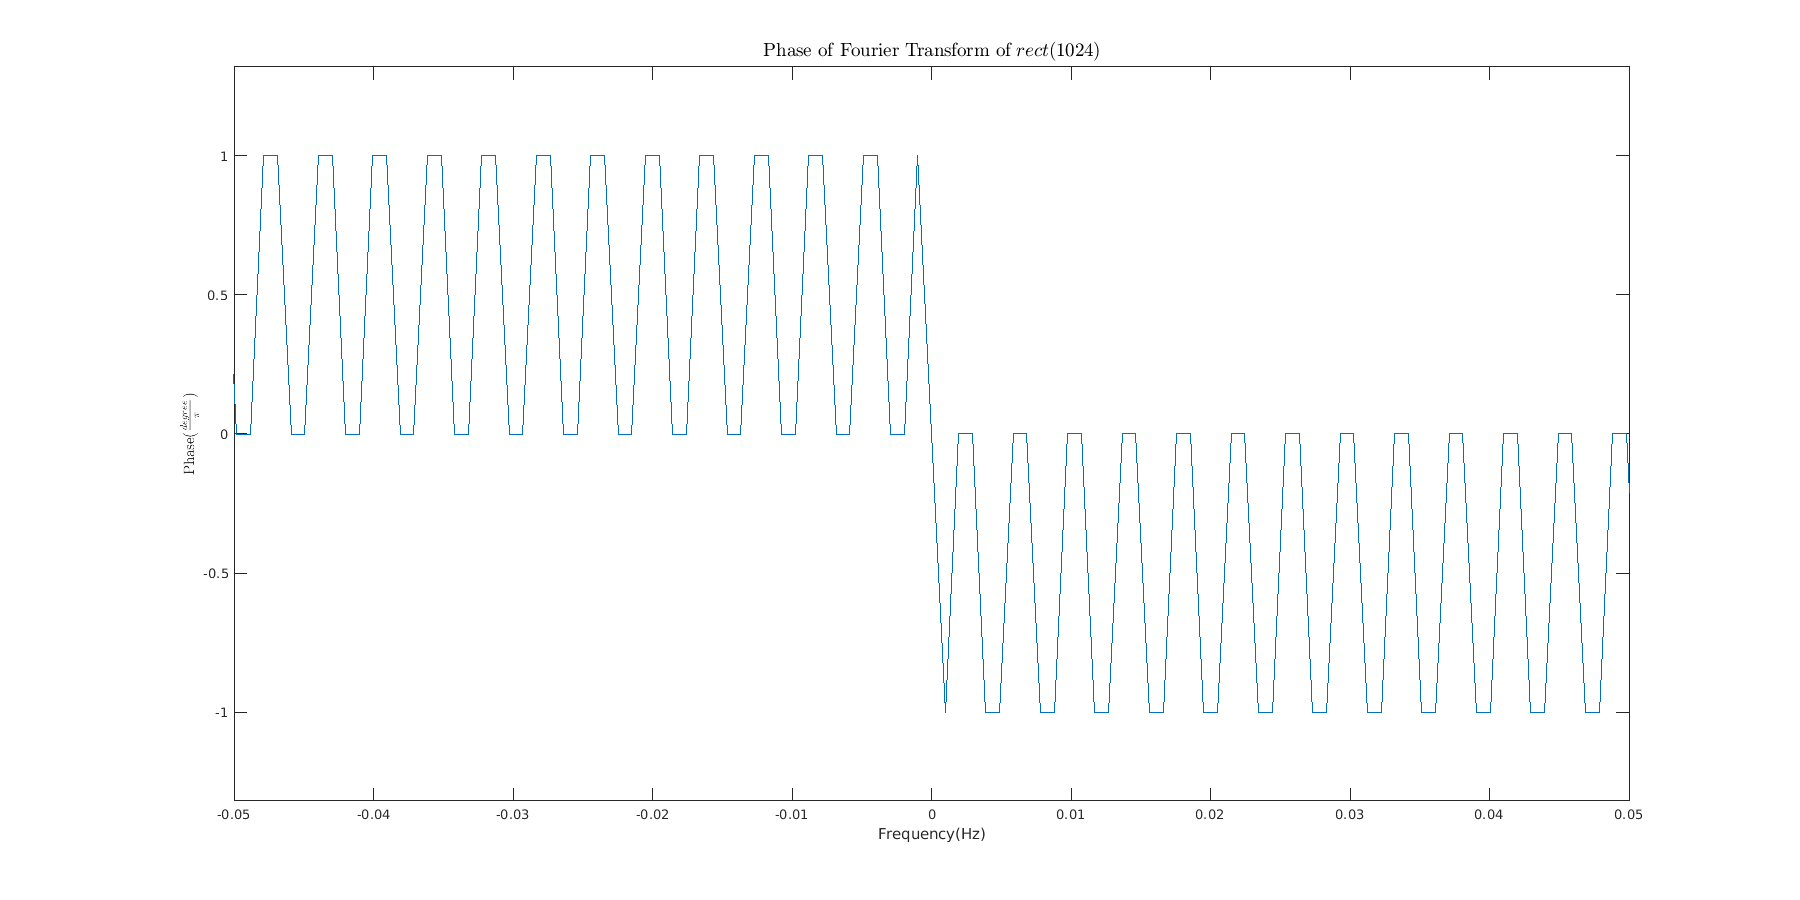

%x9
x9 = @(t) rect_func(1024,t);
time_step_9 = 0.001;
t_9 = -0:time_step_9:1024;
fs_9 = 1/time_step_9;
[w,y,freq] = ft_top_n_components(x9(t_9),4,fs_9);
plot_fourier_helper(y,w,10e-6,"$\:rect(1024)$","rect1024",[-0.1,0.1],[0,1],[-.05,0.05],[-1.1,1.1]);

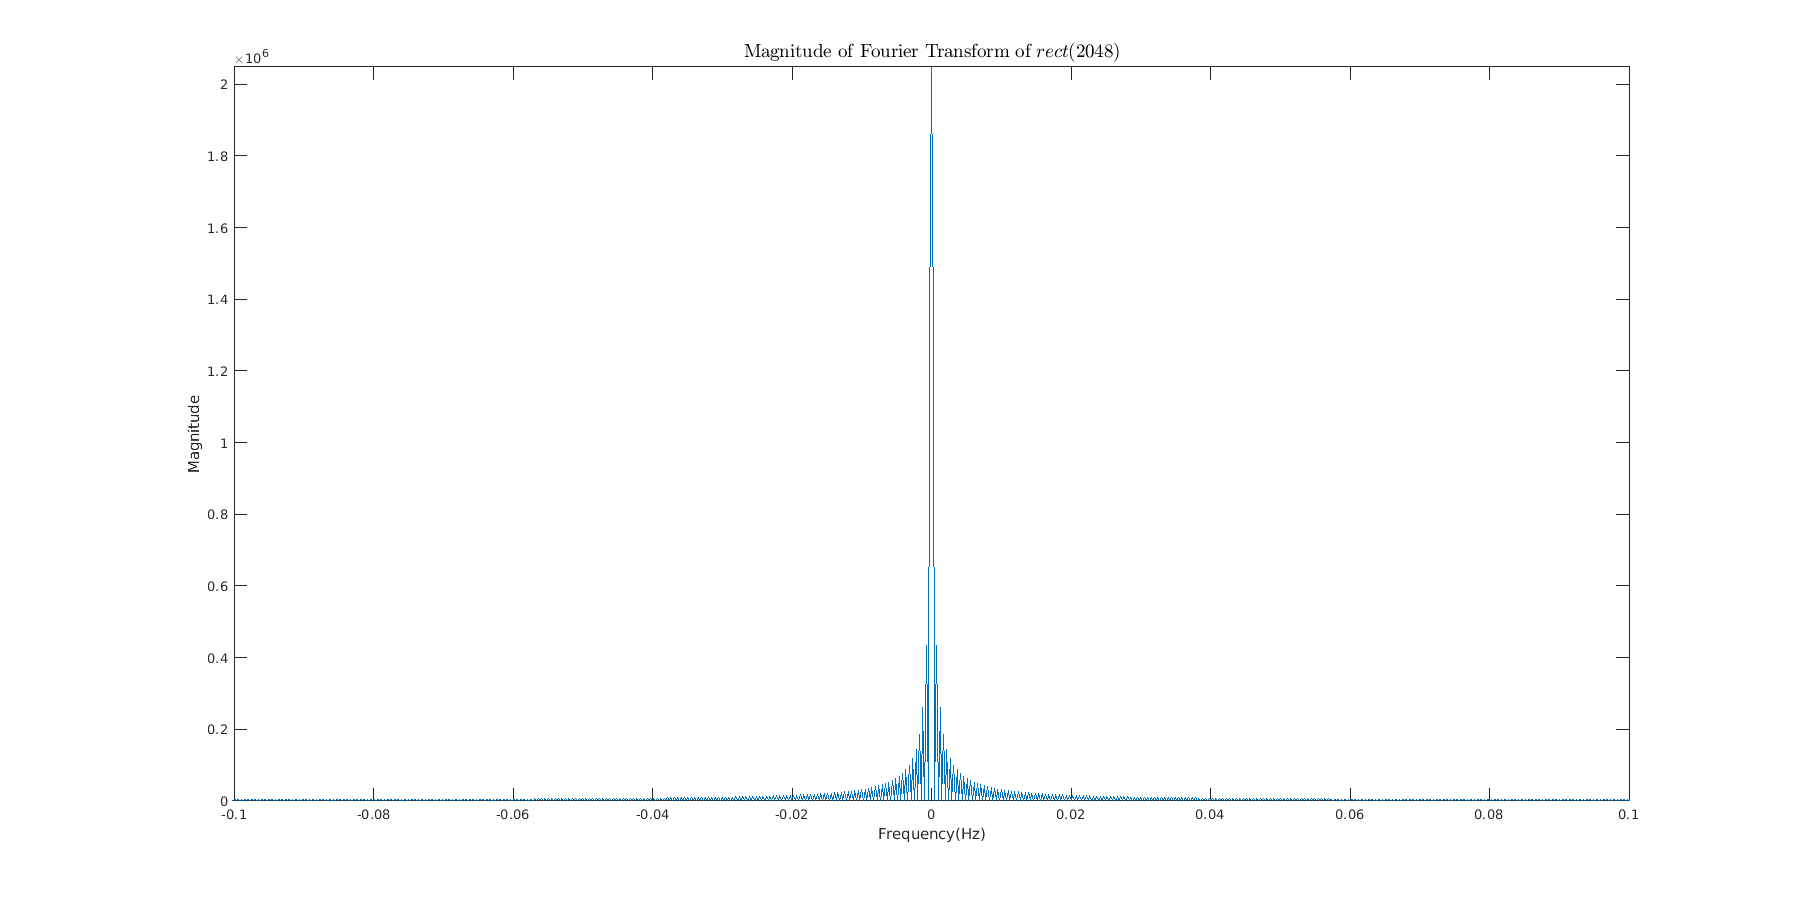

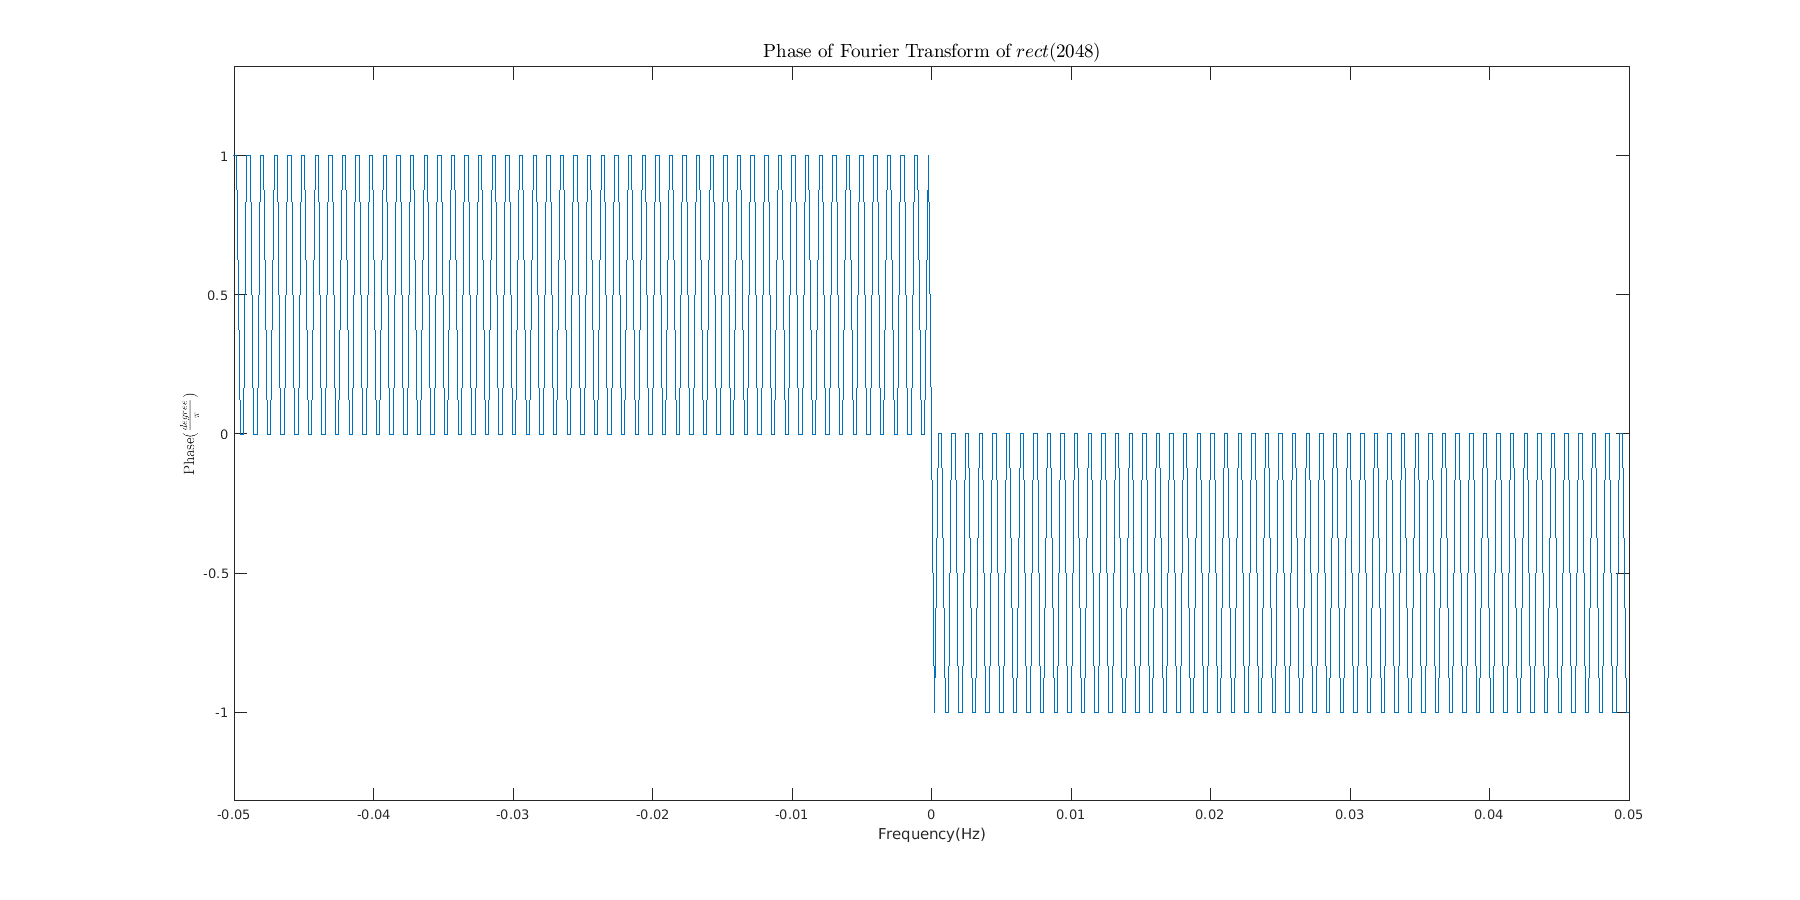

%x10
x10 = @(t) rect_func(4096,t);
time_step_10 = 0.001;
t_10 = -0:time_step_10:4096;
fs_10 = 1/time_step_10;
[w,y,freq] = ft_top_n_components(x10(t_10),4,fs_10);
plot_fourier_helper(y,w,10e-6,"$\:rect(2048)$","rect4096",[-0.1,0.1],[0,1],[-0.05,0.05],[-1.1,1.1]);